# Molico (2006) Replication

## Calibration

clear all
close all
clc

tic

mupper=700 %highest value if money holdings on the grid

mupper = 700

N=1000 %number of agents for simulating distribution

N = 1000

iterations=50 %maximum number of iterations for the value function iteration    

iterations = 50

stopping_parameter=0 %the smaller, the more does it iteration take to converge

stopping_parameter = 0

x=0.25

x = 0.2500

alpha=1

alpha = 1

theta=1

theta = 1

beta=0.99 %discount factor

beta = 0.9900

M=100 %Money supply

M = 100

r=1/beta-1 %real interest rate

r = 0.0101

mu_all=[0, 0.01, 0.05, 0.2] %Money Growth

mu_all =          0    0.0100    0.0500    0.2000


mu_labels={ 'Price Stability', 'Mild inflation'...
    , 'Medium inflation', 'high inflation'}

mu_labels = 1×4 cell array
    {'Price Stability'}    {'Mild inflation'}    {'Medium inflation'}    {'high inflation'}


n_calibration=size(mu_all)

n_calibration =      1     4


n_calibration=n_calibration(1,2)

n_calibration = 4

smoothing_parameter=0.3

smoothing_parameter = 0.3000

correct_dist=1

correct_dist = 1

## Define grid

% sets up a grid where points are located around 50-100 since under the
% most used calibration, many agents were holding money holdings in that
% range
grids_1=3

grids_1 = 3

grids_2=9

grids_2 = 9

grids_3=3

grids_3 = 3

grids=grids_1+grids_2+grids_3

grids = 15


m_0=linspace(0,80,grids_1)

m_0 =      0    40    80


m_1=linspace(90,200, grids_2)

m_1 =    90.0000  103.7500  117.5000  131.2500  145.0000  158.7500  172.5000  186.2500  200.0000


 m_2=linspace(220,mupper,grids_3);
 m=[m_0,m_1,m_2]

m =          0   40.0000   80.0000   90.0000  103.7500  117.5000  131.2500  145.0000  158.7500  172.5000  186.2500  200.0000  220.0000  460.0000  700.0000


% grids=20
% m=linspace(0,mupper, grids)


## Options



test_interpolation=0; % checks the interpolation method and displays the initial guess of the value function
test_utility=0; % displays the utility and cost function

display_plot_all=1;
display_plot_V=1;
display_plot_q=1;
display_plot_d=1;
display_plot_meeting=1;
display_plot_Distribution_rough=0;
display_plot_Distribution_smooth=1;
display_plot_cdf=0;
display_plot_money_savings=0;
display_plot_M_Track_1=1;
display_plot_q_all=1;
display_plot_d_all=1;






## set up matrixes

initial_distribution_shock=ones(1,N);
Distribution_number=ones(1,N);
Distribution_0=ones(1,N);
cdf_0=zeros(1,grids);
lamdba_0=zeros(1,grids);
m_savings_1=zeros(1,grids);
m_savings_2=zeros(1,grids);
m_savings_3=zeros(1,grids);

V_all=zeros(grids,n_calibration);
Distribution_all=zeros(N,n_calibration);
q_all=zeros(grids, grids,n_calibration);
d_all=zeros(grids, grids,n_calibration);
price_all=zeros(grids, grids,n_calibration);
f=zeros(100,n_calibration);
xi=zeros(100,n_calibration);
M_track_1=zeros(iterations,n_calibration);

average_price=zeros(1,n_calibration);
std_distribution=zeros(1,n_calibration);
velocity=zeros(1,n_calibration);
average_real_balances=zeros(1,n_calibration);

## Initial Guess

% set an initial guess for the value function
V0=log(1+m)*100  ;

 
% set an initial guess for the pdf distributiuon

for j=1:grids
if m(1,j)>M
lamdba_0(1,j)=1;
break
end
end



M_0=lamdba_0*m';

%ISSUE: the guess was choosen such that that the implied money supply is
%equal to M. But then the pdf does not sum to 1. I don't think this is a
%problem since after 


% compute cdf
for i=1:grids-1
    cdf_0(1,1)=lamdba_0(1,1);
cdf_0(1,i+1)=cdf_0(1,i)+lamdba_0(1,1+i);
end


% Draw from the initial guess
% we draw a random shock [0,1] for each individual in N. Depending on the
% initial guess, the cdf will determine the distributiuon. Notice, the
% distribution_number is determined to determine the grid point which can
% then be used to determine the money holding by using the grid m

found=0; %this parameter indicates whether a certain condition in the loop was satisfied
for i=1:N
initial_distribution_shock(1,i)=unifrnd(0,1); 
for l=1:grids 
   if initial_distribution_shock(1,i)<cdf_0(1,l)
Distribution_number(1,i)=l;
Distribution_0(1,i)=m(1,Distribution_number(1,i));
found=1;
   end
    
if found==1
found=0;
    break
end
       
end

end

 


## Test interpolation: spline, extrapolate


if test_interpolation==1
    n_interp=1000
V_interp=ones(n_interp);
m_interp=linspace(1,mupper,n_interp);
for i=1:n_interp
V_interp=interp1(m,V0,m_interp,'spline',"extrap");
end

%Plot
hold on

plot(m,V0)
plot(m_interp,V_interp)
legend('grids', 'interpolation')

hold off

clear  m_interp n_interp V_interp
end


## Test utility and cost function


if test_utility==1
u=Utility(m)
c=cost_function(m)
s=u-c
figure(1)

hold on
plot(m, u)
plot(m,c)
plot(m,s)
legend('Utility', 'Cost', 'Surplus')
title('Functional Form')
hold off
clear u c s
end

## Iteration

 for calibriation=1:n_calibration
mu=mu_all(1,calibriation);
[V_all(:,calibriation), q_all(:,:,calibriation),d_all(:,:,calibriation),Distribution_all(:,calibriation),...
    lamdba,cdf,M_track_1(:,calibriation), M_track_2,Meeting,i] = Iter_Molico_06(iterations, N,m...
     ,grids,V0,lamdba_0, cdf_0,Distribution_0,M_0,r,alpha,x,mu,theta,mupper, stopping_parameter,correct_dist)

 if cdf(grids)==1
    disp('cdf adds up to one')
else 
    disp('cdf does not add up to one')
    cdf(grids)
 end



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

stop = 0


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 =       103750           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


Distribution_new =   103.7500   97.4277  110.0723  103.7500  103.7500  110.0723   97.4277  103.7500   97.4277  110.0723  110.0723   97.4277   97.4277  110.0723  103.7500  103.7500  103.7500  103.7500  110.0723   97.4277  103.7500   97.4277  110.0723  103.7500  103.7500   97.4277  110.0723  103.7500  103.7500  103.7500   97.4277  110.0723  103.7500  110.0723   97.4277  103.7500  103.7500  103.7500  103.7500  110.0723   97.4277   97.4277  110.0723  103.7500   97.4277  110.0723  103.7500  110.0723   97.4277  110.0723


Value function has not converged


i = 1


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   109.9797   91.1979  110.0723  103.7500  103.7500  110.0723  103.9384   97.2392   91.3807  116.1193  103.5971  103.9029   91.3807  116.1193  103.7500  103.7500  103.7500  103.7500  117.0419   90.4581  103.7500   97.4277  103.5971  110.2253  109.9797   91.1979  116.4976   97.3247  103.7500   97.1456  104.0321  110.0723  103.7500  110.0723   90.9950  110.1826  109.9797   97.5203  103.7500  116.4976   91.0024   91.3807  116.1193  109.9797   91.1979  116.4976   97.3247  110.0723   90.9950  116.5050


Value function has not converged


i = 2


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   116.8796   84.2981  116.4473   97.3750  103.7500  103.2817  110.7291   97.2392   91.3807  109.0611  110.6552   97.7189   97.5648  109.4796  110.3897   97.1749  110.3251   97.1749  123.6169   90.4581   97.1749  104.0027  110.2855  103.5368  103.1930   97.9846  109.4231  104.3992  103.7500   97.1456  110.7356  103.3688  109.9303  103.8920   90.9950  110.1826  103.5925  103.9075  103.7500  123.0477   84.4523   85.1557  122.3443  103.5925   97.5851  116.4976   90.8001  116.5969   90.9950  123.0553


Value function has not converged


i = 3


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   116.8796   84.2981  109.8501  103.9722  109.9201   97.1117  117.5858   90.3825   91.3807  102.3640  117.3523   97.7189   97.5648  103.1645  116.7048   97.1749  117.1691   90.3309  116.3230   97.7521   97.1749   97.4325  116.8557  110.1701   96.5597  104.0178  103.3899  110.5877   97.5615   97.1456  103.9740  110.1304  103.2007  110.6217   90.9950  110.1826   97.0265  110.4735  110.3897  116.4080   91.1860   78.4219  122.3443  110.2275   90.9501  116.4976   90.8001  116.5969   97.4798  116.5705


Value function has not converged


i = 4


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   116.8796   91.0903  103.0579  103.9722  109.9201  103.5978  111.0996   90.3825   98.3529   95.3919  117.3523   91.4342  103.8495  109.7505  110.1188   97.1749  123.7391   83.7609  116.3230  103.8444   91.0827   97.4325  116.8557  110.1701   90.2818  110.2958  109.9814  103.9963  103.6522   91.0549   97.3949  116.7095  109.3826  104.4398   90.9950  110.1826   97.0265  110.4735  103.3541  123.4436   91.1860   84.9608  115.8055  110.2275   84.0199  123.4279   97.3363  110.0608   97.4798  116.5705


Value function has not converged


i = 5


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   116.8796   91.0903  109.2948   97.7353  109.9201  103.5978  111.0996   96.6562   92.0792   88.5273  124.2169   97.6808   97.6029  109.7505  110.1188   90.3799  130.5341   77.1287  122.9552  110.4242   84.5029   97.4325  123.4452  103.5807   90.2818  110.2958  116.7703   97.2073  109.8994   84.8077  103.9041  110.2003  116.0927   97.7296   83.5947  117.5829   90.2257  117.2743  110.3930  116.4048   84.5479   91.5988  109.2916  116.7415   84.0199  123.4279   90.5475  116.8495   97.4798  110.0276


Value function has not converged


i = 6


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   116.8796   84.3914  115.9937   91.2348  116.4206  110.1707  104.5268   96.6562   92.0792   88.5273  117.0730  104.8246  104.1477  103.2057  110.1188   90.3799  123.1655   84.4974  122.9552  110.4242   84.5029   97.4325  123.4452  103.5807   97.4098  103.1677  116.7703   90.3427  116.7640   84.8077  110.2348  103.8696  116.0927   97.7296   83.5947  117.5829   96.8866  110.6134  110.3930  116.4048   77.8123   98.3345  102.8567  123.1763   84.0199  123.4279   83.7421  123.6550   97.4798  110.0276


Value function has not converged


i = 7


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   116.8796   84.3914  122.6594   84.5691  116.4206  110.1707  104.5268  103.0988   85.6366   81.4754  124.1249   98.4127  110.5596  109.7929  103.5316   90.3799  123.1655   91.3688  116.0837  103.7286   91.1984  103.8042  117.0735  110.6244   90.3661   96.7276  123.2104   83.5672  123.5396   91.6720  103.3705  103.8696  116.0927   97.7296   76.7461  124.4315   96.8866  117.3081  103.6982  123.2428   70.9743   91.7452  109.4460  130.0414   77.1548  123.4279   90.8351  116.5619  103.9143  103.5931


Value function has not converged


i = 8


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   116.8796   84.3914  122.6594   84.5691  116.4206  110.1707  111.1549   96.4707   85.6366   88.8265  116.7738   91.5508  117.4215  116.4771   96.8474   97.1567  116.3886   84.2991  123.1534  110.2704   84.6567   97.0341  123.8436  117.5186   83.4719   89.7417  130.1963   83.5672  131.4808   83.7308  110.4263   96.8138  122.8281   90.9943   76.7461  117.3718  103.9463  117.3081   97.1553  129.7857   70.9743   91.7452  116.0417  123.4457   77.1548  123.4279   84.0088  123.3882  110.9714   96.5359


Value function has not converged


i = 9


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   116.8796   91.6895  115.3613   84.5691  123.2472  103.3440  111.1549   96.4707   78.8348   95.6282  123.5979   84.7268  117.4215  116.4771  103.5881   90.4161  116.3886   84.2991  116.1608  117.2630   78.0849  103.6058  130.8519  110.5103   76.8297   96.3838  137.3848   76.3787  131.4808   83.7308  110.4263   89.4108  130.2310   83.9535   83.7870  124.6291   96.6891  124.1447   90.3188  129.7857   65.4945   97.2250  116.0417  116.4565   84.1440  130.6002   76.8365  130.8059  103.5537   96.5359


Value function has not converged


i = 10


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   123.7791   84.7899  108.1631   91.7673  130.2994   96.2919  111.1549   96.4707   85.6137   88.8493  115.9003   92.4244  110.6776  123.2209   96.7630   97.2412  123.3316   77.3562  123.0460  110.3777   72.0284  109.6624  138.4393  102.9230   76.8297  103.2103  130.5583   76.3787  138.7080   76.5037  110.4263   96.6739  122.9680   83.9535   83.7870  124.6291  102.8727  117.9611   97.2123  122.8922   65.4945  103.4028  109.8639  109.6891   90.9114  130.6002   76.8365  123.7181  110.6415  102.7212


Value function has not converged


i = 11


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   116.9550   91.6141  108.1631   98.7099  123.3568   96.2919  111.1549  103.6893   78.3951   82.0091  122.7405   98.5513  104.5507  129.4114   90.5725   97.2412  130.3588   70.3289  123.0460  103.6579   78.7482  102.7512  145.3505   96.0113   83.7414  103.2103  130.5583   82.9842  132.1025   76.5037  117.3220   89.7781  116.0591   90.8623   90.9558  117.4603  102.8727  124.9511   90.2223  122.8922   65.4945  103.4028  109.8639  109.6891   90.9114  137.8181   69.6186  123.7181  117.4630   95.8997


Value function has not converged


i = 12


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   116.9550   91.6141  101.1619  105.7111  129.4220   90.2267  111.1549  103.6893   78.3951   88.8525  115.8972  105.5163   97.5857  129.4114   90.5725   90.4837  137.1163   65.4919  127.8831   96.6124   85.7937  109.7635  138.3381   88.9449   90.8078  103.2103  123.3635   90.1789  132.1025   76.5037  123.3057   83.7945  116.0591   83.9855   97.8325  125.1188   95.2141  132.3149   82.8585  115.8795   72.5071  103.4028  109.8639  102.7032   97.8973  137.8181   75.5594  117.7774  117.4630  102.8877


Value function has not converged


i = 13


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   116.9550   98.6496   94.1263  112.9130  122.2200   83.8414  117.5401  103.6893   85.0982   82.1493  122.9808   98.4327   97.5857  129.4114   90.5725   90.4837  137.1163   71.0191  122.3559   89.5777   92.8284  109.7635  130.2445   97.0385   97.5709   96.4471  123.3635   97.4036  124.8778   76.5037  123.3057   90.5927  109.2609   91.4254   90.3927  125.1188   95.2141  132.3149   76.7017  122.0363   67.3736  108.5363  109.8639  102.7032   90.8366  144.8787   82.4587  110.8780  110.8676  109.4831


Value function has not converged


i = 14


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   109.8561  105.7486  101.3923  105.6471  115.1052   90.9562  110.4423  110.7872   92.0927   75.1549  130.1374   91.2761  103.3879  123.6092   83.8431   97.2131  137.1163   77.0253  116.3497   96.7541   85.6520  109.7635  138.1326   89.1504   90.5169  103.5012  123.3635   90.3650  131.9165   76.5037  129.1377   84.7607  109.2609   84.7103   97.1078  125.1188   95.2141  139.2298   69.7869  122.0363   73.0581  102.8518  109.8639  102.7032   90.8366  144.8787   82.4587  110.8780  118.0976  102.2532


Value function has not converged


i = 15


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   102.4473  113.1573  108.5921   98.4473  115.1052   90.9562  110.4423  117.3874   85.4925   75.1549  137.6080   83.8055  103.3879  123.6092   83.8431  104.3891  129.9403   77.0253  116.3497   96.7541   85.6520  102.5448  145.3513   89.1504   90.5169   96.3292  130.5356   97.5272  124.7542   76.5037  129.1377   84.7607  101.1589   92.8123   90.7584  131.4682   95.2141  132.4510   76.5656  114.3061   80.7884  102.8518  117.1467   95.4204   90.8366  152.7201   74.6174  118.1578  110.8178  102.2532


Value function has not converged


i = 16


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   102.4473  113.1573  101.3222  105.7172  122.2963   83.7651  103.0092  124.8205   85.4925   81.1850  131.5779   83.8055   96.2010  130.7961   77.8640  110.3682  129.9403   77.0253  116.3497   96.7541   90.9413   97.2556  145.3513   89.1504   90.5169   96.3292  130.5356  105.6266  116.6549   76.5037  129.1377   90.8593   95.0603   86.0842   97.4865  131.4682   95.2141  138.1830   70.8337  107.2803   87.8142  110.0628  109.9357   95.4204   97.8437  145.7131   74.6174  125.4909  103.4847   95.0756


Value function has not converged


i = 17


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   109.8294  105.7753  108.5088   98.5306  122.2963   90.4494   96.3249  117.0202   93.2928   81.1850  124.5154   90.8680   96.2010  130.7961   77.8640  103.3856  136.9230   77.0253  116.3497   89.7157   97.9796   90.3149  152.2921   95.9953   83.6719   96.3292  130.5356   98.3813  123.9002   81.9224  123.7190   84.3427  101.5769   86.0842  103.8698  125.0848   95.2141  145.6642   63.3524  107.2803   94.6922  103.1847  109.9357   95.4204  104.9799  138.5769   74.6174  125.4909  103.4847   95.0756


Value function has not converged


i = 18


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   102.3752  113.2295  115.7080   91.3314  122.2963   84.0606  102.7136  109.6458  100.6672   81.1850  124.5154   84.4453  102.6237  123.2353   85.4248  103.3856  144.3291   69.6192  108.9578   97.1075   97.9796   97.1113  145.4957   95.9953   83.6719  103.5532  123.3115   92.4327  129.8488   81.9224  123.7190   84.3427   94.4669   93.1941  103.8698  125.0848   88.4721  152.4062   59.3877  111.2450   87.8677  110.0092  109.9357   95.4204  104.9799  138.5769   74.6174  125.4909  103.4847  102.0682


Value function has not converged


i = 19


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   102.3752  113.2295  108.1666   98.8728  122.2963   84.0606  110.3985  101.9609  106.8652   74.9870  117.0343   91.9263   95.4970  130.3620   79.9404  108.8699  152.2005   61.7478  100.9286  105.1368   91.1503  103.9406  145.4957  102.9257   76.7415  103.5532  115.8329   99.9113  129.8488   76.3712  129.2702   84.3427   94.4669   86.6446  110.4193  125.0848   88.4721  160.4227   51.3712  118.4188   80.6939  110.0092  109.9357  102.8869   97.5134  138.5769   69.7518  130.3565  109.7277   95.8252


Value function has not converged


i = 20


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   102.3752  105.7807  115.6154   98.8728  129.8190   76.5380  116.5976   95.7618  106.8652   70.5262  121.4951   98.5658   88.8575  137.9421   72.3603  108.8699  143.5128   70.4354  100.9286  105.1368   97.7495   97.3414  152.9507   95.4707   72.5503  107.7445  115.8329   93.0578  136.7022   76.3712  121.6243   91.9886  102.2025   78.9091  115.7013  119.8029   88.4721  152.1908   59.6032  118.4188   75.2860  115.4171  102.6569  110.1657   97.5134  138.5769   64.9404  135.1678  109.7277   95.8252


Value function has not converged


i = 21


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =   109.7407   98.4152  108.0987  106.3895  129.8190   76.5380  116.5976   95.7618  100.3343   77.0571  113.8325  106.2284   88.8575  137.9421   72.3603  108.8699  143.5128   70.4354  107.8232   98.2422   97.7495  104.6010  145.6911   88.8387   79.1823  100.3920  123.1854   93.0578  136.7022   76.3712  126.8563   86.7565   95.1210   85.9905  121.8317  113.6725   95.7316  144.9313   59.6032  126.2467   67.4581  108.6687  109.4053  110.1657  104.7808  131.3095   64.9404  135.1678  109.7277   95.8252


Value function has not converged


i = 22


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0         0


Distribution_new = 1×1000
  103.2282  104.9276  102.3205  112.1677  136.9223   69.4346  123.6462   88.7132  100.3343   77.0571  120.8649   99.1960   95.5786  131.2211   72.3603  115.8499  136.5329   66.5451  111.7135  103.1441   92.8476  104.6010  145.6911   95.4606   72.5604   94.9200  128.6574   86.9045  142.8555   76.3712


Value function has not converged


i = 23


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0         0


Distribution_new = 1×1000
  110.5389   97.6170  109.0439  105.4443  129.3910   76.9660  115.9612   96.3982  100.3343   72.3771  125.5449   99.1960  100.2870  126.5127   72.3603  115.8499  142.5960   60.4820  111.7135  103.1441   92.8476  104.6010  145.6911   95.4606   68.6105   98.8699  135.7001   79.8618  134.9180   84.3088


Value function has not converged


i = 24


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0         0


Distribution_new = 1×1000
  103.2365  104.9193  102.0983  112.3899  129.3910   76.9660  108.7379  103.6215  100.3343   77.7228  120.1992  106.5861   92.8969  118.2248   80.6483  123.7580  134.6879   57.1734  115.0221   97.1738   98.8179   97.5483  152.7437   95.4606   64.6938  102.7866  135.7001   79.8618  134.9180   84.3088


Value function has not converged


i = 25


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0         0


Distribution_new = 1×1000
   96.3321  111.8237  102.0983  112.3899  137.0294   69.3276  101.1236  111.2358  107.3733   70.6838  120.1992  106.5861   85.8155  125.3061   80.6483  130.6587  127.7872   53.7943  118.4011   97.1738   93.8115  102.5548  160.6698   87.5346   64.6938  102.7866  135.7001   85.1057  129.6741   90.3444


Value function has not converged


i = 26


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0         0


Distribution_new = 1×1000
   96.3321  117.4609   96.4611  119.0675  130.3518   74.1841   96.2670  111.2358  107.3733   75.8954  114.9875   99.9926   92.4090  125.3061   76.8379  134.4691  127.7872   56.3573  115.8381  102.3729   88.6124  102.5548  152.3939   95.8105   64.6938  102.7866  127.5451   93.2607  121.0044   99.0141


Value function has not converged


i = 27


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0         0


Distribution_new = 1×1000
   90.1916  123.6014   96.4611  112.7935  136.6258   69.8497  100.6015  118.5432  100.0659   75.8954  107.4922  107.4880   92.4090  117.4309   84.7132  126.5884  135.6679   60.4278  111.7677  108.6163   82.3689  102.5548  146.4225  101.7818   64.6938  102.7866  127.5451   87.6900  126.5751   99.0141


Value function has not converged


i = 28


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375         0


Distribution_new = 1×1000
   90.1916  123.6014   96.4611  119.2782  130.1411   65.8226  104.6286  125.9669   92.6422   72.1628  111.2248  115.1394   84.7576  117.4309   79.4055  131.8961  135.6679   64.5176  107.6779  108.6163   82.3689  102.5548  146.4225   95.1783   71.2973   96.2629  134.0688   87.6900  119.3642  106.2251


Value function has not converged


i = 29


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   90.1916  129.1507   90.9118  119.2782  130.1411   69.7847  100.6665  125.9669   86.9701   77.8349  106.0798  120.2844   88.4677  113.7207   79.4055  136.6874  130.8766   64.5176  107.6779  116.7997   74.1856  102.5548  137.8110  103.7898   74.9504   92.6099  127.6590   94.0997  126.7389   98.8503


Value function has not converged


i = 30


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   90.1916  129.1507   86.8680  123.3220  124.5537   75.3722   94.9249  131.7085   83.1419   81.6630  106.0798  120.2844   88.4677  113.7207   79.4055  143.3387  124.2253   64.5176  107.6779  116.7997   74.1856  109.6618  130.7040  103.7898   74.9504   99.2614  121.0075   94.0997  126.7389   98.8503


Value function has not converged


i = 31


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   86.2714  133.0709   88.4579  121.7321  124.5537   72.2336   98.0635  131.7085   87.9295   76.8755  106.0798  120.2844   88.4677  113.7207   79.4055  143.3387  131.5582   57.1846  115.2299  109.2477   69.9508  113.8966  123.6158  110.8780   74.9504   99.2614  113.6630  101.4442  118.5515  107.0377


Value function has not converged


i = 32


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   82.2279  137.1143   88.4579  121.7321  124.5537   73.5917   96.7054  124.6719   94.9661   81.7892  101.1661  120.2844   92.0899  110.0985   75.3140  147.4301  123.8762   64.8667  121.3717  103.1059   69.9508  118.2860  119.2264  115.1993   70.6291   93.0184  119.9060  101.4442  125.6641   99.9251


Value function has not converged


i = 33


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   82.2279  137.1143   93.3282  116.8618  124.5537   73.5917   96.7054  124.6719   94.9661   77.0695  105.8858  120.2844   92.0899  115.0255   70.3870  147.4301  123.8762   64.8667  114.7947  109.6829   69.9508  118.2860  127.4325  106.9932   70.6291   96.7293  116.1951  108.7019  118.4065  106.1157


Value function has not converged


i = 34


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   82.2279  145.1572   85.2854  116.8618  132.9325   65.2130   96.7054  124.6719   94.9661   82.5730  100.3822  120.2844   92.0899  115.0255   74.2368  143.5803  130.9635   57.7794  122.5748  101.9028   73.1962  115.0406  119.6495  114.7762   75.8224   91.5360  120.4973  104.3997  111.1026  113.4196


Value function has not converged


i = 35


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   82.2279  145.1572   85.2854  116.8618  125.4043   72.7412  103.0554  118.3218   94.9661   82.5730  100.3822  113.9626   98.4117  115.0255   74.2368  150.9289  123.6148   57.7794  127.6545   96.8231   73.1962  119.9403  114.7498  114.7762   72.8808   94.4776  120.4973  104.3997  117.6372  106.8851


Value function has not converged


i = 36


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   87.5978  139.7873   81.9566  120.1906  125.4043   77.1081   98.6884  118.3218  101.4520   76.0871  100.3822  121.5999   90.7745  119.1734   70.0890  150.9289  123.6148   57.7794  119.9782  104.4994   73.1962  126.7238  107.9663  114.7762   78.0207   89.3376  124.7608  100.1362  117.6372  100.5010


Value function has not converged


i = 37


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   87.5978  146.0050   75.7388  120.1906  125.4043   80.0439   95.7526  124.9506   94.8233   76.0871  100.3822  121.5999   85.4608  124.4871   66.2271  154.7908  123.6148   57.7794  119.9782  108.9099   68.7857  126.7238  103.1661  119.5764   74.3475   93.0108  124.7608  100.1362  117.6372  100.5010


Value function has not converged


i = 38


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   89.0662  144.5367   75.7388  120.1906  119.9102   85.5380   89.7477  130.9555   94.8233   72.5805  103.8889  114.4058   92.6549  118.2619   72.4523  162.0813  116.3242   60.3206  117.4370  108.9099   66.0193  129.4901   97.1998  125.5427   70.2081   97.1503  131.5181   93.3789  117.6372  100.5010


Value function has not converged


i = 39


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   84.1561  149.4468   75.7388  120.1906  119.9102   85.5380   89.7477  130.9555   94.8233   77.6181   98.8512  114.4058   92.6549  123.8359   66.8783  156.5050  121.9006   60.3206  124.5633  101.7836   66.0193  129.4901   97.1998  125.5427   67.6767   99.6817  131.5181   97.2479  113.7682   95.6590


Value function has not converged


i = 40


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   84.1561  149.4468   80.0117  115.9178  125.4523   79.9959   84.6575  136.0457   94.8233   74.8177  101.6516  121.8131   85.2476  128.5932   62.1210  165.2011  113.2045   57.2470  127.6368  101.7836   62.5762  132.9333   92.6245  130.1180   65.0367  102.3217  131.5181   97.2479  113.7682   95.6590


Value function has not converged


i = 41


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   84.1561  158.0218   71.4367  120.4016  120.9685   82.8549   81.7984  136.0457   94.8233   74.8177  107.7872  115.6775   85.2476  128.5932   62.1210  165.2011  117.0194   53.4321  122.2909  107.1296   66.4712  129.0382   97.0221  125.7204   65.0367  102.3217  131.5181  103.8447  107.1714   95.6590


Value function has not converged


i = 42


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   84.1561  158.0218   67.8387  123.9996  113.6212   90.2022   78.6011  139.2431   91.3948   78.2462  107.7872  120.9134   80.0116  123.8233   66.8909  159.6805  122.5400   57.1397  118.5833  102.1603   71.4405  134.6871   91.3732  125.7204   65.0367  108.8933  124.9464   99.0534  111.9627   95.6590


Value function has not converged


i = 43


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   84.1561  158.0218   67.8387  116.5048  121.1160   85.2241   83.5791  139.2431   91.3948   78.2462  103.4461  125.2545   82.7961  121.0388   70.0752  156.4962  127.9249   51.7548  118.5833  102.1603   71.4405  134.6871   91.3732  129.7137   61.0434  108.8933  124.9464   99.0534  111.9627   91.3776


Value function has not converged


i = 44


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   84.1561  162.3819   63.4786  116.5048  129.2705   77.0696   83.5791  139.2431   91.3948   82.4067   99.2856  129.1917   78.8590  116.1773   74.9367  151.1511  133.2701   51.7548  118.5833  100.1502   73.4506  134.6871   91.3732  133.7369   57.0203  114.4781  119.3617   94.1849  116.8312   95.5260


Value function has not converged


i = 45


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   84.1561  169.3712   56.4893  120.2030  125.5723   77.0696   83.5791  143.3787   87.2592   82.4067   99.2856  126.6618   81.3888  116.1773   74.9367  151.1511  130.6717   54.3532  125.8440   92.8896   73.4506  134.6871   95.4616  129.6485   59.3131  112.1852  119.3617   94.1849  121.0948   91.2624


Value function has not converged


i = 46


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   81.0237  172.5035   58.4705  118.2218  125.5723   81.0661   79.5826  143.3787   87.2592   82.4067   99.2856  126.6618   85.0384  112.5278   74.9367  151.1511  124.1856   60.8393  119.6066   99.1269   70.1270  138.0107   98.5701  126.5400   59.3131  112.1852  119.3617   94.1849  121.0948   91.2624


Value function has not converged


i = 47


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   76.6780  176.8493   60.4909  116.2014  125.5723   78.0988   82.5499  136.3921   94.2457   87.0995   94.5928  119.9119   91.7883  108.2237   79.2407  156.9296  118.4071   64.3983  116.0476   94.0571   75.1968  138.0107   98.5701  126.5400   63.4451  108.0532  113.5565   99.9902  128.8043   83.5529


Value function has not converged


i = 48


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   72.9890  180.5383   58.1194  118.5729  125.5723   74.9329   85.7158  140.3644   90.2735   87.0995   94.5928  124.8578   86.8424  103.1098   84.3547  161.1629  114.1738   64.3983  116.0476   94.0571   75.1968  142.0097   94.5712  126.5400   63.4451  111.4164  110.1933  103.5951  125.1993   83.5529


Value function has not converged


i = 49


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   75.7177  177.8095   60.7281  115.9642  119.0462   81.4590   90.4584  135.6218   95.2344   82.1385   94.5928  124.8578   86.8424  103.1098   80.2650  165.2525  118.8653   59.7067  116.0476   97.4363   71.8176  137.2046   99.3762  126.5400   60.9676  113.8938  110.1933  109.7607  119.0338   80.8301


Value function has not converged


i = 50

V_all = 15×4
    0.0016         0         0         0
  589.3485         0         0         0
  778.8743         0         0         0
  799.7255         0         0         0
  821.7827         0         0         0
  838.5281         0         0         0
  851.7841         0         0         0
  862.8163         0         0         0
  872.5090         0         0         0
  881.4258         0         0         0


q_all = q_all(:,:,1) =

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.9139    0.8606    0.7409    0.7112    0.6692    0.6287    0.5928    0.5646    0.5454    0.5322    0.5210    0.5070    0.4873    0.2328    0.0000
    0.9538    0.9240    0.8549    0.8371    0.8118    0.7872    0.7654    0.7485    0.7371    0.7290    0.7217    0.7122    0.6999    0.5210    0.0000
    0.9587    0.9319    0.8696    0.8536    0.8307    0.8085    0.7889    0.7738    0.7636    0.7564    0.7498    0.7411    0.7300    0.5657    0.0000
    0.9642    0.9408    0.8860    0.8719    0.8517    0.8320    0.8148    0.8016    0.7928    0.7865    0.7805    0.7727    0.7630    0.6142    0.0000
    0.9684    0.9476    0.8987    0.8861    0.8681    0.8506    0.8352    0.8237    0.8160    0.8103    0.8050    0.7979    0.7892    0.6539    0.0000
    0.9715    0.9526    0.9084    0.8969    0.8805    0.8647    0.8510

d_all = d_all(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4779    0.7396    1.2415    1.3470    1.4829    1.5994    1.6907    1.7549    1.7949    1.8189    1.8360    1.8525    1.8776    1.6310         0
    0.9339    1.4728    2.5977    2.8586    3.2163    3.5508    3.8409    4.0669    4.2208    4.3216    4.4000    4.4905    4.6312    5.8993         0
    1.0517    1.6628    2.9530    3.2559    3.6743    4.0692    4.4151    4.6868    4.8728    4.9953    5.0908    5.2031    5.3767    7.0835         0
    1.2224    1.9374    3.4620    3.8234    4.3255    4.8030    5.2244    5.5574    5.7861    5.9372    6.0549    6.1964    6.4130    8.6853         0
    1.3937    2.2138    3.9776    4.3992    4.9879    5.5510    6.0509    6.4479    6.7207    6.9014    7.0418    7.2144    7.4757   10.3416         0
    1.5531    2.4728    4.4672    4.9478    5.6214    6.2693    6.8476

Distribution_all = 1000×4
   75.7177         0         0         0
  177.8095         0         0         0
   60.7281         0         0         0
  115.9642         0         0         0
  119.0462         0         0         0
   81.4590         0         0         0
   90.4584         0         0         0
  135.6218         0         0         0
   95.2344         0         0         0
   82.1385         0         0         0


lamdba = 1×15
         0    0.0220    0.2310    0.1000    0.1540    0.1580    0.1340    0.0810    0.0630    0.0290    0.0170    0.0070    0.0030    0.0010         0


cdf = 1×15
         0    0.0220    0.2530    0.3530    0.5070    0.6650    0.7990    0.8800    0.9430    0.9720    0.9890    0.9960    0.9990    1.0000    1.0000


M_track_1 = 50×4
  108.4387         0         0         0
  109.7312         0         0         0
  110.0750         0         0         0
  109.9663         0         0         0
  110.1912         0         0         0
  110.2512         0         0         0
  110.4762         0         0         0
  110.3812         0         0         0
  110.2825         0         0         0
  109.9400         0         0         0


M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Meeting = 1×1000
     4     6     5     3     7     5     7     3     7     8     9     7     6     6     7     3     5     8     8     4     8     3     8     5     5     3    11     8     9     3


i = 0

cdf adds up to one



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

stop = 0


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0273         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   97.4800  110.0200  103.7500  103.7500  110.0200   97.4800   97.4800  110.0200  103.7500  110.0200   97.4800   97.4800  110.0200  103.7500  103.7500  110.0200   97.4800   97.4800  110.0200  103.7500  103.7500  103.7500   97.4800  110.0200  103.7500  103.7500  103.7500   97.4800  110.0200  110.0200


Value function has not converged


i = 1


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0273         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   97.4806  110.0194   97.5566  109.9434  110.0194   91.3054  103.6558  103.6278  110.1415  110.0194   97.4806   97.4806  116.9543   96.8150  103.7500  110.0194  103.4936   91.4677  110.0194  109.9434   97.5566  109.9434   91.2872  110.0194  110.4641   97.0359  109.9434   91.2872  110.0194  116.4197


Value function has not converged


i = 2


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0273         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   97.4812  110.0188   97.5572  109.9428  110.0188   84.7616  110.2009   96.9894  116.7794  110.0188   97.4812  104.0185  110.4158   90.4632  110.1024  110.0188  109.7017   85.2608  103.6798  116.2817   97.5572  109.9428   97.8755  103.4317  110.4634   90.6915  116.2879   91.2884  110.0188  116.4185


Value function has not converged


i = 3


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   97.4818  103.5445  104.0314  116.4042  103.5562   77.6541  117.3096   96.9900  116.7781  116.9454   90.5546  104.0185  110.4151   90.4645  103.3625  116.7574  109.7011   85.2626  109.9983  109.9621   90.6329  116.8671   90.9660  110.3418  110.4628   83.9379  123.0416   97.9842  103.3236  116.4173


Value function has not converged


i = 4


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  103.9197   97.1072  110.5261  109.9083  110.2117   71.0011  117.3083  103.5239  110.2436  123.8827   83.6173  104.0185  103.9385   96.9418  103.3626  123.5294  102.9273   78.2055  117.0565  109.9615   90.6342  116.8658   97.7927  103.5157  110.4621   91.4592  115.5203  104.6653   96.6431  116.4161


Value function has not converged


i = 5


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   96.9999  104.0277  110.5255  109.9077  110.2111   71.0042  117.3070  103.5239  110.2430  130.9951   76.5049  104.0184   96.9810  103.9000  103.3626  116.6191  109.8358   71.9204  123.3428  109.9609   97.5996  109.9004  104.6073   96.7017  117.2239   84.6980  122.6785   97.5059   89.6882  123.3705


Value function has not converged


i = 6


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   97.0006  104.0277  110.5248  103.0463  117.0712   71.0074  117.3057   96.5546  117.2118  138.4556   69.0444  110.8861   90.1139  103.8999  103.3626  116.6178  116.6945   65.0642  116.3518  116.9494   97.6002  103.0390  111.4680   96.7024  110.2525   91.6699  122.6766   90.3933   96.8027  123.3686


Value function has not converged


i = 7


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   89.7384  111.2904  110.5242   95.8266  124.2897   71.0105  117.3044  103.7325  110.0332  146.2420   61.2580  103.7942   97.2065  111.1064   96.1563  116.6166  123.9044   57.8567  109.3058  123.9930   97.6008  110.2594  104.2469   96.7031  102.7856   99.1373  122.6748   90.3946   89.1782  130.9919


Value function has not converged


i = 8


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   89.7398  111.2897  110.5235   95.8273  124.2878   71.0137  117.3031   96.3687  117.3965  146.2379   61.2621  103.7942   90.3097  118.0031   96.1570  108.7474  131.7705   57.8612  102.0053  131.2909   97.6014  117.6102   96.8954   96.7038  110.2221   91.7013  129.6967   83.3721   89.1797  138.1911


Value function has not converged


i = 9


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   89.7411  118.7868  103.0250   95.8281  124.2858   66.1533  122.1653   89.0057  124.7589  146.2338   61.2662   96.3158   97.7894  118.0017   96.1577  108.7469  139.4427   50.1906  102.0055  123.6253  105.2649  125.0873   89.4177   89.2172  117.7087   99.2143  122.1824   83.3741   89.1811  138.1878


Value function has not converged


i = 10


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   89.7425  118.7853   95.0069  103.8470  124.2838   61.8501  126.4704   89.0071  117.3974  153.5892   61.2703  103.9368   90.1697  118.0003   96.1585  116.3720  131.8137   50.1958  102.0057  123.6234  105.2647  125.0852   96.7788   81.8589  117.7073   99.2147  127.8680   77.6887   82.5232  144.8437


Value function has not converged


i = 11


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   89.7438  118.7839   95.0078  103.8470  124.2818   61.8541  126.4682   89.0085  124.9961  145.9844   61.2744   96.3302   97.7775  110.1680  103.9901  108.6098  139.5720   54.0949   98.1119  131.3732   97.5129  125.0832  104.4437   74.1968  117.7060  106.9449  120.1360   72.3607   87.8557  151.7531


Value function has not converged


i = 12


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   96.7662  111.7614  102.6006   96.2550  124.2799   61.8581  126.4660   89.0099  131.4939  139.4804   57.5176  100.0918   97.7781  110.1674  111.8916  100.7078  139.5686   58.1966   94.0155  139.2800   89.6041  125.0811  110.9645   67.6788  125.3053   99.3440  120.1344   72.3638   87.8573  145.0054


Value function has not converged


i = 13


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   89.8094  118.7181  102.6007   96.2557  124.2779   66.5959  121.7302   82.7125  137.7900  139.4770   60.6556   96.9586   97.7787  110.1668  111.8908  108.0962  132.1770   62.6570   89.5604  132.0314   96.8506  118.7401  117.3027   63.4528  129.5327   99.3444  127.6893   64.8103   92.6212  140.2390


Value function has not converged


i = 14


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   96.8858  111.6416  107.7127   91.1446  116.2444   74.6310  128.0027   76.4403  137.7868  147.8229   52.3104   96.9592   97.7793  102.4740  119.5821  115.5154  124.7547   58.9044   93.3183  132.0287   96.8513  125.0159  111.0242   68.2705  124.7164   92.2120  134.8198   64.8141   86.0869  146.7709


Value function has not converged


i = 15


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   96.8865  104.0287  115.3244   86.3797  121.0092   70.1323  132.5018   82.3049  131.9215  139.3648   60.7692   96.9599  105.3004   94.9536  119.5806  107.3943  132.8727   58.9088   93.3193  123.6363  105.2416  125.0139  111.0235   68.2740  118.5495   98.3779  143.2122   56.4225   86.0886  154.2616


Value function has not converged


i = 16


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   96.8872  112.0895  107.2625   86.3814  121.0076   70.1356  132.4991   77.8594  136.3663  139.3614   57.7620   99.9719  105.3003   94.9544  119.5791   99.8041  140.4597   58.9131   97.7392  119.2155  110.0858  120.1675  111.0228   72.0994  114.7260  105.7702  135.8167   56.4270   86.0903  154.2568


Value function has not converged


i = 17


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   96.8878  104.2293  115.1216   80.7846  126.6044   75.3615  127.2736   81.4218  132.8033  139.3579   60.4588   97.2799  105.3001   90.3384  124.1945  107.5315  132.7291   63.3005   93.3567  128.0057  101.2935  112.5055  118.6825   72.1025  106.7969  113.6980  127.1045   65.1407   86.0920  154.2519


Value function has not converged


i = 18


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  104.4106   96.7071  120.7763   75.1310  134.7264   67.2400  127.2714   76.3683  137.8561  131.4265   68.3910   90.9203  111.6602   94.3035  120.2287  100.2897  139.9677   59.7465   96.9156  128.0034  107.5687  106.2296  110.2881   80.4985  115.0524  105.4412  127.1022   65.1445   86.0937  163.1106


Value function has not converged


i = 19


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  104.4105   90.3698  127.1127   79.6183  130.2389   67.2436  127.2691   79.6195  134.6043  131.4238   64.4462   94.8696  111.6595   94.3044  120.2271   95.1355  145.1188   62.3493   94.3177  128.0010  112.8163  100.9814  110.2875   75.7601  119.7919  111.6994  120.8416   65.1482   86.0954  163.1049


Value function has not converged


i = 20


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  104.4105   90.3710  127.1104   76.3569  133.5000   67.2471  127.2668   83.4331  130.7900  131.4212   64.4500   94.8705  111.6587   88.5548  125.9760   89.8337  150.4174   66.8380   89.8339  135.9135  104.9006   96.5327  114.7358   80.7757  114.7775  120.0605  112.4781   65.1519   82.4861  166.7101


Value function has not converged


i = 21


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  112.2795   82.5033  127.1082   80.6071  129.2496   71.5964  122.9188   83.4351  137.4713  124.7346   64.4538   94.8714  104.1742   96.0400  120.5037   95.3052  150.4129   69.5415   87.1353  140.6333  100.1776  100.9701  110.2981   86.6742  108.8801  126.4899  106.0463   67.7960   79.8478  158.8232


Value function has not converged


i = 22


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0         0


Distribution_new = 1×1000
  120.0405   74.7434  118.4727   89.2425  129.2472   67.8232  126.6932   89.4662  131.4389  117.8490   71.3412   89.4183  109.6281  102.0220  114.5208   95.3060  158.2937   61.6595   91.8011  135.9656  106.4187   94.7297  118.3819   78.5915  102.9910  132.3763  112.6426   61.2029   79.8501  152.9541


Value function has not converged


i = 23


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0         0


Distribution_new = 1×1000
  120.0389   79.7868  113.4307   89.2439  137.6599   59.4115  120.8212   95.3374  131.4362  117.8476   71.3443   89.4197  109.6275  102.0222  114.5198   95.3068  158.2884   61.6636   97.9828  129.7819  106.4184   88.9076  124.2034   78.5939  102.9911  132.3735  106.0085   67.8402   79.8524  152.9494


Value function has not converged


i = 24


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0         0


Distribution_new = 1×1000
  120.0374   76.0969  117.1220   93.7087  133.1933   63.0240  117.2113   90.1746  136.5972  117.8462   71.3475   89.4210  104.0823  107.5670  107.9540  101.8724  158.2832   59.4534  100.1976  124.5739  111.6237   88.9090  124.2014   78.5963  102.9911  124.6314  113.7477   67.8437   79.8547  145.4306


Value function has not converged


i = 25


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0         0


Distribution_new = 1×1000
  115.3652   80.7702  117.1207   93.7096  141.4132   54.8052  112.6675   94.7184  136.5940  117.8449   71.3506   84.4325  109.0722  111.2878  104.2324  105.9690  154.1814   59.4576   94.0276  130.7422  111.6230   88.9104  132.0305   70.7676   98.6728  128.9478  113.7468   67.8471   82.6985  142.5851


Value function has not converged


i = 26


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0         0


Distribution_new = 1×1000
  123.2062   72.9303  117.1194   93.7106  145.8098   50.4097  112.6667   94.7192  140.9202  113.5142   71.3537   84.4344  109.0717  105.3419  110.1775  105.9688  154.1766   56.3021   97.1883  130.7395  107.4621   93.0720  132.0278   70.7708   95.1045  132.5142  108.3018   73.2945   82.7005  142.5814


Value function has not converged


i = 27


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0         0


Distribution_new = 1×1000
  123.2043   76.9054  113.1459   90.4475  149.0698   50.4148  106.2501  101.1358  134.1874  120.2424   73.8249   81.9682  115.6519   98.7611  116.8226   99.3229  144.2490   66.2295   92.8629  135.0630  110.9916   89.5431  124.2077   78.5914   95.1053  132.5114  108.3014   73.2975   82.7026  142.5776


Value function has not converged


i = 28


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273         0


Distribution_new = 1×1000
  123.2025   72.8032  117.2498   90.4488  156.1994   43.2861  106.2499  107.7047  127.6158  120.2408   70.4268   85.3713  115.6507  103.1150  112.4680   99.3233  137.5372   72.9410   97.6622  130.2618  110.9909   85.7370  128.0132   82.1399   91.5601  140.1326  100.6770   70.8738   85.1312  142.5739


Value function has not converged


i = 29


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0273


Distribution_new = 1×1000
  129.2817   66.7251  117.2485   90.4500  149.1970   50.2892  106.2496  103.0587  132.2591  123.9485   66.7207   82.2816  118.7410  109.0024  106.5798  102.4613  134.3964   70.5735  100.0332  130.2592  105.5715   91.1574  122.2588   87.8940   88.5318  143.1585  105.7115   65.8428   82.3438  145.3593


Value function has not converged


i = 30


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  129.2792   66.7286  117.2472   90.4513  149.1926   48.2537  108.2900   99.6554  135.6598  117.2615   73.4093   82.2837  114.6990  113.0425  103.0360  106.0049  134.3934   70.5767  100.0335  130.2567  105.5714   91.1587  122.2570   87.8956   84.1490  147.5390  105.7113   62.6946   85.4978  152.0914


Value function has not converged


i = 31


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  129.2768   64.1297  119.8484   90.4526  157.8745   39.5728  103.3174  104.6281  139.5669  113.3501   69.9409   85.7571  114.6979  108.9341  107.1436  102.2051  138.1900   70.5799   95.0681  135.2200  100.7532   95.9779  122.2552   87.8971   89.3244  142.3613  111.4227   56.9870   85.4995  152.0867


Value function has not converged


i = 32


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  129.2743   64.1336  119.8469   90.4539  157.8693   41.1133  101.7830   99.5061  144.6853  108.7794   74.5139   90.9085  109.5472  108.9336  107.1433  102.2053  138.1867   70.5831   95.0689  135.2169  106.0720   90.6601  122.2534   83.4148   93.8096  149.6443  104.1352   56.9915   91.4129  146.1705


Value function has not converged


i = 33


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  129.2718   64.1374  116.0294   94.2710  148.9246   50.0589  101.7832  103.3692  140.8186  108.7789   74.5167   94.4809  105.9755  113.1234  102.9526  102.2054  133.6703   75.0994   95.0697  135.2139  111.5123   85.2208  122.2516   83.4168   96.9357  146.5148  109.4831   51.6480   96.1678  141.4127


Value function has not converged


i = 34


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  134.8267   58.5838  116.0283   94.2720  154.2725   44.7118  101.7834  100.2261  143.9582  112.8690   70.4290   94.4818  111.9365  107.1612   99.0665  106.0917  133.6674   77.6735   92.4992  129.8218  116.9006   89.6043  117.8681   85.8913   94.4638  146.5107  105.3055   55.8300   99.8369  137.7407


Value function has not converged


i = 35


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  138.9360   54.4759  112.5021   97.7978  158.2551   40.7300  101.7836   95.6840  148.4968  107.6347   75.6656   94.4827  116.0413  103.0553   99.0670  106.0915  129.4972   81.8433   88.7339  133.5858  111.9564   94.5486  117.8668   89.1689   91.1888  146.5066  110.4529   50.6872   95.7350  141.8397


Value function has not converged


i = 36


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  144.5782   48.8351  119.1568   91.1428  153.3161   45.6699  101.7838   99.7366  144.4406  112.1247   71.1779   94.4836  116.0401  103.0554   99.0674  106.0913  129.4948   85.4179   85.1628  137.1114  108.4271   94.5495  121.4611   85.5746   91.1901  150.2919  106.6628   52.8857   93.5424  145.5349


Value function has not converged


i = 37


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  150.2848   43.1298  119.1554   91.1440  146.0677   52.9191   98.8504  102.6706  137.0491  119.5115   71.1810   89.4950  121.0284  109.9783   92.1450  101.8743  133.7090   89.0440   81.5403  137.1082  103.2321   99.7450  117.0342   90.0015   91.1913  150.2874  104.7171   54.8359   88.6110  150.4633


Value function has not converged


i = 38


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  150.2803   41.2317  121.0578   87.9905  149.2184   52.9240  103.4084   98.1132  137.0459  116.0566   74.6375   91.9626  118.5606  106.8348   95.2890   98.3260  137.2546   92.2418   78.3460  145.4905   94.8466  104.9120  111.8662   90.0028   91.1925  150.2829  107.5083   52.0494   85.8772  153.1940


Value function has not converged


i = 39


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  150.2758   41.2378  121.0561   90.3972  146.8089   54.6144  101.7229   98.1137  143.0117  110.0864   74.6403   88.1397  122.3831  106.8345   95.2898   98.3266  137.2514   92.2429   78.3484  141.2212   99.1127  104.9119  111.8655   86.9381   94.2597  150.2784  110.3192   49.2431   88.9398  150.1284


Value function has not converged


i = 40


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  142.4359   49.0793  121.0545   90.3984  146.8047   54.6191  101.7231   95.4115  145.7107  105.9389   78.7900   84.5424  125.9802  103.2251   98.8998   98.3271  137.2481   92.2441   78.3509  141.2176   99.1131  104.9118  108.0678   90.7366   91.4312  153.1033  106.5800   52.9869   88.9412  150.1239


Value function has not converged


i = 41


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  146.9370   44.5796  121.0528   90.3997  151.4215   50.0029   98.3530   98.7826  149.2064  102.4390   76.1685   87.1681  125.9780  100.4155  101.7100  100.8800  134.6925   92.2452   75.4707  144.0967   99.1136  101.4300  111.5491   90.7379   91.4324  153.0986  106.5797   56.3765   85.5580  150.1195


Value function has not converged


i = 42


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  146.9329   44.5853  121.0511   90.4010  151.4169   50.0081   94.8011  102.3355  156.8010   94.8401   80.4911   82.8498  129.0458   97.3458  105.0449   97.5455  134.6895   94.6522   73.0674  144.0928   94.5082  106.0360  111.5483   87.7775   94.3953  153.0938  106.5795   56.3810   82.7606  152.9141


Value function has not converged


i = 43


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  146.9287   44.5910  125.9697   85.4820  147.2342   54.1914   94.8019  102.3356  156.7959   98.8614   76.4729   85.0610  126.8343   94.7607  107.6306   97.5461  128.2463  101.0933   73.0704  140.1423   98.4557  106.0358  111.5476   90.0778   92.0974  156.6276  103.0407   54.4601   84.6882  156.4447


Value function has not converged


i = 44


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  146.9246   46.2171  124.3472   85.4838  147.2300   54.1962   92.3088  104.8297  152.5092  103.1435   76.4755   85.0628  126.8320   94.7615  104.2108  100.9661  128.2439  105.2526   68.9143  140.1388   95.8705  108.6213  111.5468   90.0791   92.0985  160.1768   99.4864   52.1152   87.0397  156.4396


Value function has not converged


i = 45


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  146.9204   48.8817  121.6862   85.4856  143.3010   58.1258   92.3099  101.5463  155.7879  107.8042   71.8175   85.0646  130.6531   90.9391  100.2578  104.9193  123.7343  109.7598   67.0463  142.0066   98.5411  105.9511  114.2335   87.3930   88.3068  163.9642   99.4868   52.1201   90.6998  152.7760


Value function has not converged


i = 46


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  146.9162   46.6724  123.8991   89.0494  139.7350   61.1654   89.2758   98.0822  159.2472  107.8038   74.2910   82.5959  133.6583   87.9326  100.2582  102.2266  126.4250  112.6835   64.1256  138.2895  102.2550  105.9509  114.2325   87.3946   88.3083  163.9584  103.4684   48.1440   90.7010  146.8048


Value function has not converged


i = 47


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  142.3101   51.2799  123.8971   93.0928  135.6896   58.3279   92.1188   98.0827  159.2418  112.4767   69.6205   79.0270  137.2263   87.9341  100.2585  102.2267  130.6393  108.4661   64.1294  145.3598   95.1815  105.9506  114.2315   84.9585   90.7474  159.6417  107.7793   49.8039   89.0478  146.8007


Value function has not converged


i = 48


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  138.6823   54.9083  120.5137   96.4746  135.6861   56.7256   93.7262   98.0829  164.2850  107.4265   72.3036   76.3491  141.1360   84.0220  100.2585  102.2265  130.6363  108.4653   64.1330  150.0288   90.5085  102.0983  118.0819   84.9600   92.9989  157.3853  107.7785   49.8089   86.0631  149.7818


Value function has not converged


i = 49


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  141.7281   51.8639  124.9459   92.0415  139.5091   52.9040   89.7878  102.0228  164.2791  111.4729   68.2598   73.9972  143.4869   80.4774  103.8054  102.2267  130.6337  108.4648   66.0952  148.0659   90.5097  104.7849  115.3940   84.9618   89.3652  161.0149  107.7781   49.8141   89.1331  146.7091


Value function has not converged


i = 50

V_all = 15×4
    0.0016    6.5117         0         0
  589.3485  508.6487         0         0
  778.8743  708.0322         0         0
  799.7255  735.3071         0         0
  821.7827  765.7326         0         0
  838.5281  789.8348         0         0
  851.7841  809.1213         0         0
  862.8163  824.7159         0         0
  872.5090  837.4794         0         0
  881.4258  848.0796         0         0


q_all = q_all(:,:,1) =

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.9139    0.8606    0.7409    0.7112    0.6692    0.6287    0.5928    0.5646    0.5454    0.5322    0.5210    0.5070    0.4873    0.2328    0.0000
    0.9538    0.9240    0.8549    0.8371    0.8118    0.7872    0.7654    0.7485    0.7371    0.7290    0.7217    0.7122    0.6999    0.5210    0.0000
    0.9587    0.9319    0.8696    0.8536    0.8307    0.8085    0.7889    0.7738    0.7636    0.7564    0.7498    0.7411    0.7300    0.5657    0.0000
    0.9642    0.9408    0.8860    0.8719    0.8517    0.8320    0.8148    0.8016    0.7928    0.7865    0.7805    0.7727    0.7630    0.6142    0.0000
    0.9684    0.9476    0.8987    0.8861    0.8681    0.8506    0.8352    0.8237    0.8160    0.8103    0.8050    0.7979    0.7892    0.6539    0.0000
    0.9715    0.9526    0.9084    0.8969    0.8805    0.8647    0.8510

d_all = d_all(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4779    0.7396    1.2415    1.3470    1.4829    1.5994    1.6907    1.7549    1.7949    1.8189    1.8360    1.8525    1.8776    1.6310         0
    0.9339    1.4728    2.5977    2.8586    3.2163    3.5508    3.8409    4.0669    4.2208    4.3216    4.4000    4.4905    4.6312    5.8993         0
    1.0517    1.6628    2.9530    3.2559    3.6743    4.0692    4.4151    4.6868    4.8728    4.9953    5.0908    5.2031    5.3767    7.0835         0
    1.2224    1.9374    3.4620    3.8234    4.3255    4.8030    5.2244    5.5574    5.7861    5.9372    6.0549    6.1964    6.4130    8.6853         0
    1.3937    2.2138    3.9776    4.3992    4.9879    5.5510    6.0509    6.4479    6.7207    6.9014    7.0418    7.2144    7.4757   10.3416         0
    1.5531    2.4728    4.4672    4.9478    5.6214    6.2693    6.8476

Distribution_all = 1000×4
   75.7177  141.7281         0         0
  177.8095   51.8639         0         0
   60.7281  124.9459         0         0
  115.9642   92.0415         0         0
  119.0462  139.5091         0         0
   81.4590   52.9040         0         0
   90.4584   89.7878         0         0
  135.6218  102.0228         0         0
   95.2344  164.2791         0         0
   82.1385  111.4729         0         0


lamdba = 1×15
         0    0.0100    0.2040    0.1350    0.1660    0.1840    0.1270    0.0790    0.0570    0.0220    0.0100    0.0050    0.0010         0         0


cdf = 1×15
         0    0.0100    0.2140    0.3490    0.5150    0.6990    0.8260    0.9050    0.9620    0.9840    0.9940    0.9990    1.0000    1.0000    1.0000


M_track_1 = 50×4
  108.4387  108.2600         0         0
  109.7312  109.5938         0         0
  110.0750  110.1575         0         0
  109.9663  110.3187         0         0
  110.1912  110.3287         0         0
  110.2512  110.3500         0         0
  110.4762  110.4000         0         0
  110.3812  110.3900         0         0
  110.2825  110.6737         0         0
  109.9400  110.5012         0         0


M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Meeting = 1×1000
     3     9     7     8     5     3     9     9     8     7     6     5     5     9     5     5     7     3     4     6     7     4     3     3     8     3     7     3     6     6


i = 0.0100

cdf adds up to one



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

stop = 0


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+04 *

    9.8857         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  109.9340   97.5660  103.7500  103.7500   97.5660  109.9340   97.5660  109.9340  103.7500  103.7500  103.7500  109.9340   97.5660  103.7500  109.9340   97.5660  103.7500  103.7500  103.7500  103.7500  109.9340   97.5660  103.7500   97.5660  109.9340  103.7500   97.5660  109.9340  103.7500  109.9340


Value function has not converged


i = 1


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    0.9886         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  116.6635   90.8365  103.7500  103.7500   97.5690  109.9310   90.1582  117.3418  110.4737   97.0263  103.7500  109.9310   90.1582  111.1607  116.7444   90.7556  103.7500  110.4737   97.0263   96.6672  117.0138  104.5226   96.7964   97.5690  116.6635   97.0175   97.5690  109.9310   96.6672  117.0138


Value function has not converged


i = 2


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    0.9886         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  109.2890   98.2110  111.5341   95.9659   89.7589  117.7411   97.9119  109.5881  102.9076  104.5924  103.7500  102.5542   97.5386  111.1572  116.7381   98.9936   95.5182  103.1162  104.3838   88.8754  124.8027  112.2721   89.0499  105.2056  109.0237   97.0207   97.5720  109.9280  104.3395  109.3385


Value function has not converged


i = 3


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  101.2103  106.2897  119.3574   88.1426   89.7656  125.3969   90.2522  109.5853  111.2268   96.2732  103.7500   94.5217  105.5747  111.1536  116.7319   91.1361  103.3820  103.1165  104.3835   88.8825  116.6798  120.3807   89.0569   97.1133  117.1128  105.5886   89.0103  109.9251  112.8184  100.8567


Value function has not converged


i = 4


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  110.1726   97.3274  119.3499   88.1501   82.9264  132.2324   90.2587  109.5825  111.2232   96.2768   96.0190  102.2571   96.8992  119.8247  107.6876  100.1802  103.3822   94.6277  112.8723   88.8897  107.9018  129.1445   82.1538  104.0267  117.1063  114.6412   79.9639  109.9221  112.8140  109.3237


Value function has not converged


i = 5


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  119.4924   88.0076  127.5696   79.9304   82.9365  132.2187   98.0519  101.7929  111.2196   96.2804   96.0227  111.2258   87.9345  119.8170  107.6857  100.1819   95.1717  102.8427  112.8679   84.0498  112.7468  138.1971   73.0994   97.0456  124.0808  105.4415   89.1698  101.3167  121.4121  100.7688


Value function has not converged


i = 6


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  119.4848   88.0152  135.4401   72.0599   82.9465  132.2050   92.3431  107.5055  111.2160   96.2840  104.2509  102.9977   87.9421  119.8093  115.1763   92.6911  101.7932   96.2258  121.9794   74.9434  112.7425  138.1805   73.1142   97.0488  115.1939  114.3178   89.1769   93.7296  128.9919  106.4458


Value function has not converged


i = 7


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  111.5724   95.9276  135.4249   72.0751   88.9683  126.1795   86.2559  113.5964  111.2124   96.2876  104.2507  102.9981   87.9497  119.8015  106.6827  101.1846  101.7942  102.2012  115.9988   70.2255  117.4700  148.2991   62.9937   97.0521  124.8230  104.6781   93.6482   89.2701  120.4602  114.9640


Value function has not converged


i = 8


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  111.5686   95.9314  125.9517   81.5483   94.8687  120.2754   91.0492  108.8067  118.7358   88.7642  104.2504  102.9984   87.9573  119.7938   99.7915  108.0756  101.7951  102.2020  115.9929   70.2417  117.4634  148.2776   63.0134   97.0553  124.8128   99.6179   98.7128   89.2771  128.5869  106.8239


Value function has not converged


i = 9


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  104.9044  102.5956  132.3440   75.1560   98.8478  116.2926   95.6556  104.2040  118.7286   92.4983  100.5233  102.9988   87.9649  119.7861  106.7932  101.0737  101.7960   97.0525  121.1372   75.7574  111.9572  138.7702   72.5190   97.0585  117.9590  106.4636  104.6750   83.3242  122.4489  112.9485


Value function has not converged


i = 10


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   98.7172  108.7828  138.4691   69.0309   98.8502  109.1218  102.8242  104.2038  118.7214   92.5037  100.5249  102.9992   84.0529  123.6980  106.7918  101.0750  101.7970   93.5714  124.6132   80.7709  106.9532  138.7533   72.5340  101.5570  113.4569  100.1480  110.9888   86.6276  119.1463  112.9440


Value function has not converged


i = 11


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   98.7196  108.7804  133.2356   74.2644   98.8526  109.1192  102.8247   99.7456  123.1722   92.5091  100.5264  108.1822   78.8797  123.6884  100.4134  107.4532  101.7979   93.5763  124.6031   84.3603  103.3733  131.2587   80.0268   96.6692  118.3411   94.7772  116.3579   93.4048  112.3700  107.9922


Value function has not converged


i = 12


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   98.7220  114.6326  127.3668   70.9537  102.1798  109.1166  102.8251   99.7475  123.1628   92.5145   96.0400  112.6681   74.6382  127.9323  105.0980  102.7684   96.7138   98.6663  128.3440   80.6187  103.3735  131.2455   77.4496   99.2613  118.3341   91.0398  120.0935   93.4098  112.3658  107.9901


Value function has not converged


i = 13


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   98.7244  118.8832  123.0995   68.2034  104.9467  109.1140  109.4733   93.1017  123.1535   92.5199  101.6087  107.0987   70.4906  132.0823  101.8437  106.0225  100.3943   94.9916  122.0272   86.9348  107.2569  127.3490   77.4623  103.0181  114.5724   91.0459  124.5320   88.9684  112.3617  107.9881


Value function has not converged


i = 14


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   94.8145  122.7883  127.3786   63.9322  104.9461  109.1114  109.4706   88.6054  127.6455   95.9215   98.2137  107.0971   70.5066  136.6515   97.2618  106.0214  100.3960   91.9341  125.0801   90.6642  103.5340  131.7640   73.0486   99.3436  118.2420   87.4261  128.1479   88.9755  107.3902  112.9534


Value function has not converged


i = 15


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   94.8188  127.3989  122.7474   67.7779  101.1190  112.7928  105.7838   92.7023  123.5444   95.9252   98.2163  107.0955   70.5226  131.3241  102.5764  106.0203  100.3976   89.0540  127.9556   90.6705  106.6545  128.6301   73.0634   99.3458  118.2350   87.4340  128.1361   88.9827  110.5953  109.7421


Value function has not converged


i = 16


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   94.8231  127.3875  127.6830   62.8505  104.9025  109.0062  105.7829   95.8810  120.3615   95.9290   94.9580  110.3549   70.5386  126.5384  107.3495  106.0192  100.3992   92.5445  124.4605   94.6420  102.6878  128.6181   73.0781  102.6669  114.9090   84.9094  130.6568   86.2433  113.3384  109.7392


Value function has not converged


i = 17


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   97.6329  124.5706  124.2186   66.3231  107.6467  106.2590  105.7819   99.0414  117.1969   99.4616   91.4334  106.8505   74.0558  126.5274  104.4159  108.9499   96.8776   96.0731  119.7633   99.3337  102.6883  131.7794   69.9197  102.6674  114.9036   84.9185  130.6438   86.2518  110.0496  113.0205


Value function has not converged


i = 18


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   97.6358  128.2272  120.5421   63.5368  110.4492  108.9823  103.0564  102.5405  113.6935   96.0619   94.8411  106.8490   74.0701  126.5164  104.4156  104.9751  100.8531   96.0768  119.7556   99.3358  102.6888  131.7659   69.9360   99.7112  117.8550   82.1322  133.4262   82.6720  113.6347  108.9156


Value function has not converged


i = 19


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   97.6388  128.2154  120.5340   63.5561  106.2414  113.1844  106.5512   99.0466  117.7908   91.9635   94.8454  104.0206   76.9113  130.4986  100.4222  104.9745  100.8545   99.4370  116.3914   99.3379  102.6893  127.8641   73.8406  103.1410  114.4204   79.4429  136.1117   82.6822  116.6637  105.8794


Value function has not converged


i = 20


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   97.6417  128.2037  123.9470   60.1544  106.2402  113.1798  103.1173  102.4815  117.7841   88.8711   97.9478  104.0204   76.9243  130.4857  100.4238  101.3231  104.5068   99.4391  113.2237  102.5017  105.8003  124.7420   73.8550   99.7888  117.7676   76.8327  138.7179   85.7469  113.6030  103.0998


Value function has not converged


i = 21


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   97.6446  128.1919  123.9372   60.1754  106.2390  109.6469  106.6459   99.1942  121.0651   88.8782   94.7608  107.2102   76.9372  134.0102   96.8880  104.6639  101.1668   99.4411  108.8842  106.8372  109.2178  121.3134   76.7299   96.9302  117.7609   73.7257  141.8211   85.7555  116.3474  100.3509


Value function has not converged


i = 22


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0         0


Distribution_new = 1×1000
   97.6476  124.6144  127.4933   60.1964  106.2378  109.6441  109.4872   96.3538  117.6426   92.2996   94.7651  107.2085   79.3851  131.5606   94.1533  107.4015  101.1680  102.7118  105.6131  103.4940  112.5569  121.3049   79.0102   94.6662  121.3316   70.1627  141.8028   82.8600  119.2456  103.9231


Value function has not converged


i = 23


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0         0


Distribution_new = 1×1000
   94.7149  127.5399  123.7386   63.9606  109.5855  106.2923  109.4844  100.0962  113.8971   94.7714   92.3031  107.2068   79.3969  127.4645   98.2406  110.0486   98.5204   99.2782  109.0463  103.4941  112.5527  121.2965   79.0222   91.6011  124.3926   72.3606  139.6027   85.8476  116.2605  103.9230


Value function has not converged


i = 24


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0         0


Distribution_new = 1×1000
   90.8813  131.3664  119.8807   67.8281  109.5827  110.1615  105.6112   97.3145  116.6757   94.7757   92.3086  104.3035   82.3102  127.4531   98.2433  110.0456   95.5791  102.2242  105.5080  107.0299  108.9393  124.8972   79.0341   94.7086  121.2810   72.3757  139.5855   83.1431  118.9677  103.9229


Value function has not converged


i = 25


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0         0


Distribution_new = 1×1000
   93.9698  128.2708  116.1425   71.5758  109.5799  106.4245  109.3443   97.3176  116.6695   98.9527   88.1415  104.3033   79.8321  129.9302  101.4382  106.8503   98.5032   99.3047  108.8070  103.7285  108.9368  121.0534   82.8796   94.7130  117.9310   75.7324  136.1217   86.5995  118.9604  101.2186


Value function has not converged


i = 26


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0         0


Distribution_new = 1×1000
   97.0991  125.1344  116.1365   71.5913  112.4420  103.5583  109.3416   94.2256  119.7583   95.8303   91.2737  104.3030   79.8436  129.9176  101.4393  106.8488   95.2151  102.5975  108.8046  103.7285  105.0577  124.9216   80.0690   97.5379  117.9241   73.3583  138.4937   86.6078  115.0632  105.1097


Value function has not converged


i = 27


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0         0


Distribution_new = 1×1000
   93.8433  128.3832  116.1305   74.5757  109.4689  106.8203  106.0770   91.3550  122.6258   95.8341   94.8062  100.7762   77.2368  132.5232   98.4441  109.8436   95.2192   99.4080  111.9922  103.7285  108.5730  121.3955   82.9983   94.6231  117.9173   71.0139  140.8360   89.0449  112.6289  108.6257


Value function has not converged


i = 28


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886         0


Distribution_new = 1×1000
   96.7610  125.4584  119.5603   71.1540  106.5166  109.7684  109.8336   87.6032  118.8841   99.5705   91.7543  103.8340   79.7313  130.0277   98.4467  109.8406   92.6245  102.0089  111.9883  100.6874  111.6118  121.3870   85.4060   92.2297  117.9105   71.0297  144.5837   85.2864  109.2556  111.9924


Value function has not converged


i = 29


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.9886


Distribution_new = 1×1000
   94.1311  128.0811  122.7981   67.9243  109.6007  106.6800  109.8307   87.6110  118.8768   96.1047   95.2278  103.8339   83.2592  126.4987   98.4492  109.8377   92.6299  104.8112  109.1828  100.6889  108.2519  124.7346   87.8529   89.7972  117.9037   71.0455  144.5641   85.2953  112.8264  108.4150


Value function has not converged


i = 30


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   94.1357  124.8232  126.0352   67.9416  106.1002  110.1763  109.8277   87.6188  115.5653   99.4127   92.1498  106.9160   83.2690  130.3056   94.6340  109.8348   95.1677  102.2782  109.1802  103.9311  105.0090  127.7898   84.7953   89.8039  117.8968   68.5666  147.0390   82.4069  115.7193  111.5327


Value function has not converged


i = 31


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   96.8749  122.0785  122.5978   71.3855  106.0991  113.0922  106.9058   85.1068  118.0793   99.4147   92.1554  104.1104   86.0829  130.2928   94.6384  113.4256   91.5781  102.2789  109.1776  103.9310  102.0915  130.6951   81.7654   92.8497  117.8900   70.8249  144.7768   82.4171  112.7856  114.4569


Value function has not converged


i = 32


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   96.8782  122.0696  119.0186   74.9712  106.0980  116.0521  103.9398   82.1978  120.9904   96.0828   95.4950  104.1103   89.7228  126.6486   97.2230  110.8407   88.3969  105.4667  111.9098  101.1961  102.0923  130.6821   79.3378   95.2930  121.5987   67.1253  141.2533   85.9311  109.3736  117.8594


Value function has not converged


i = 33


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   96.8815  119.0195  122.0526   74.9850  109.4500  112.6931  100.6673   85.4806  125.1900   91.8787   95.4990  107.2185   86.6212  126.6376   94.2282  113.8352   88.4043  105.4659  111.9059  101.1973  102.0931  126.5997   83.4191   92.4999  124.3874   67.1429  144.7706   82.4043  112.5438  114.6797


Value function has not converged


i = 34


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   96.8848  122.3143  118.7416   72.6459  111.8002  115.6773   97.6803   85.4894  125.1797   91.8844   92.3618  110.3580   86.6294  126.6266   94.2328  117.5180   84.7240  105.4650  111.9019  101.1985  102.0939  126.5887   86.2790   89.6551  120.5747   70.9633  141.2244   85.9411  112.5395  111.7204


Value function has not converged


i = 35


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   96.8881  125.6612  115.3785   69.7089  114.7483  118.5111   94.8437   88.1805  122.4870   91.8901   92.3673  107.2998   89.6927  126.6155   94.2374  113.9787   88.2659  105.4642  111.8980  101.1998  102.0947  126.5777   89.9492   86.0001  124.5777   66.9679  141.2063   85.9497  116.0047  108.2473


Value function has not converged


i = 36


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   94.1642  128.3779  111.6925   73.4057  111.4162  121.8308   98.4860   84.5499  126.3155   88.0583   92.3728  107.2981   92.2737  124.0302   97.2693  110.9464   85.6801  108.0566  114.9030   98.1920   99.2920  129.3702   89.9559   86.0086  128.4326   63.1207  137.8530   89.2935  112.4740  111.7698


Value function has not converged


i = 37


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   94.1688  124.6226  115.4321   76.5184  108.3143  118.1840  102.1267   87.2544  123.6093   88.0659   95.3952  104.2794   94.8949  121.4048   97.2725  114.6415   81.9902  104.1937  118.7585  101.2892   96.1997  126.1619   93.1585   86.0172  128.4208   63.1403  134.1437   92.9934  112.4698  111.7659


Value function has not converged


i = 38


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   97.2290  121.5570  115.4265   76.5315  108.3121  118.1771   98.6525   90.7373  123.5998   84.8732   98.5996  104.2791   94.8992  125.4724   93.1995  118.6148   78.0222  101.0050  121.9398  101.2904   96.2034  130.2940   89.0207   86.0257  128.4089   65.7224  131.5665   92.9985  109.3343  114.8934


Value function has not converged


i = 39


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   97.2321  124.7039  112.2654   74.1157  110.7389  114.7401  102.0850   90.7436  127.0257   81.4467   95.3288  107.5521   97.7547  122.6106   89.8845  121.9277   81.0641   97.9768  121.9310  104.6766   92.8220  130.2812   86.3883   88.6738  132.1342   62.0035  134.5963   89.9606  113.2495  110.9702


Value function has not converged


i = 40


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   97.2352  120.6124  116.3427   71.3288  113.5367  110.9950  105.8256   90.7498  130.0278   78.4442   92.5818  110.3014   94.4850  125.8742   93.1247  118.6854   81.0750  100.8808  119.0210  108.3373   89.1660  127.0173   89.6478   91.2865  129.5151   62.0236  130.8840   93.6646  109.8780  114.3336


Value function has not converged


i = 41


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   94.4472  123.3955  120.1827   67.4983  116.4240  108.0994  109.5197   87.0610  130.0151   78.4564   92.5872  110.2982   94.4895  122.0883   96.9050  118.6783   81.0859  100.8822  119.0137  108.3351   89.1731  122.8636   93.7971   91.2925  133.5262   58.0202  127.4275   97.1129  109.8750  110.5788


Value function has not converged


i = 42


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   97.9871  119.8506  120.1748   70.1993  113.7344  108.0973  109.5169   87.0690  130.0025   78.4685   89.7253  113.1623   94.4939  122.0795   96.9083  121.8352   77.9327  100.8836  115.8833  111.4560   85.9013  126.1332   96.4870   88.6133  133.5119   58.0422  124.0074  100.5248  109.8721  114.3570


Value function has not converged


i = 43


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   97.9899  116.1353  123.8745   70.2154  113.7296  104.9655  112.6440   87.0771  133.5593   74.9112   92.5606  110.3293   90.9552  125.6138   96.9116  121.8265   77.9451  100.8849  112.2382  115.0915   89.6852  122.3471   93.6911   91.4200  133.4976   55.1066  126.9553   97.3317  113.0638  114.3519


Value function has not converged


i = 44


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   97.9926  119.5491  120.4450   70.2316  113.7248  108.4755  109.1290   87.0851  133.5450   78.1436   89.3474  107.1498   94.1377  125.6033   94.0996  124.6331   77.9576   97.6738  115.4466  115.0860   89.6920  122.3382   93.6959   91.4260  136.6034   52.0100  122.9176  101.3613  113.0593  118.4320


Value function has not converged


i = 45


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   94.4968  123.0401  120.4370   70.2477  113.7200  105.4718  112.1279   90.1323  130.4914   75.2217   92.2886  110.4663   90.8241  122.1714   97.5256  124.6230   75.0397  100.6071  115.4410  111.4266   93.3527  122.3292   93.7008   88.0680  139.9515   52.0349  126.9139   97.3569  113.0548  122.1337


Value function has not converged


i = 46


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   94.5013  123.0308  120.4289   67.2464  116.7326  105.4709  107.8862   94.3765  130.4786   72.3539   95.1757  113.5782   87.7153  118.9498  100.7413  124.6129   75.0535   97.3794  118.6645  111.4229   93.3577  126.0940   89.9319   88.0755  139.9340   49.9319  129.0307   97.3600  113.0503  125.1547


Value function has not converged


i = 47


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   91.2094  126.3179  124.4220   63.2629  119.9232  102.2733  111.7008   90.5645  134.0934   68.7413   97.9218  110.8315   87.7230  118.9425  103.7487  121.5969   77.9302   94.5196  118.6573  114.3461   90.4358  126.0832   87.2140   90.8077  139.9166   52.1614  126.8149   93.7066  116.7023  120.6135


Value function has not converged


i = 48


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   88.1402  129.3822  128.4836   59.2108  123.6831   98.5063  115.5842   86.6836  130.6785   72.1584   97.9246  110.8281   91.2309  115.4350  106.5981  118.7390   77.9427   94.5240  118.6502  117.7842   86.9991  126.0725   90.5078   87.5281  136.4194   55.6660  130.4001   90.1151  116.6960  120.6054


Value function has not converged


i = 49


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   88.1477  124.7174  133.1242   61.6167  121.2891   98.5088  112.4347   89.8357  126.6893   76.1498   97.9274  114.2323   87.8294  111.9127  110.1134  118.7318   77.9551   94.5285  121.6621  114.7583   87.0071  122.5895   93.9864   84.5256  139.4140   58.3681  127.7083   90.1217  120.4255  116.8616


Value function has not converged


i = 50

V_all = 15×4
    0.0016    6.5117   19.8286         0
  589.3485  508.6487  298.8221         0
  778.8743  708.0322  434.9225         0
  799.7255  735.3071  457.7413         0
  821.7827  765.7326  485.3446         0
  838.5281  789.8348  509.5453         0
  851.7841  809.1213  531.0929         0
  862.8163  824.7159  550.5146         0
  872.5090  837.4794  568.1943         0
  881.4258  848.0796  584.4214         0


q_all = q_all(:,:,1) =

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.9139    0.8606    0.7409    0.7112    0.6692    0.6287    0.5928    0.5646    0.5454    0.5322    0.5210    0.5070    0.4873    0.2328    0.0000
    0.9538    0.9240    0.8549    0.8371    0.8118    0.7872    0.7654    0.7485    0.7371    0.7290    0.7217    0.7122    0.6999    0.5210    0.0000
    0.9587    0.9319    0.8696    0.8536    0.8307    0.8085    0.7889    0.7738    0.7636    0.7564    0.7498    0.7411    0.7300    0.5657    0.0000
    0.9642    0.9408    0.8860    0.8719    0.8517    0.8320    0.8148    0.8016    0.7928    0.7865    0.7805    0.7727    0.7630    0.6142    0.0000
    0.9684    0.9476    0.8987    0.8861    0.8681    0.8506    0.8352    0.8237    0.8160    0.8103    0.8050    0.7979    0.7892    0.6539    0.0000
    0.9715    0.9526    0.9084    0.8969    0.8805    0.8647    0.8510

d_all = d_all(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4779    0.7396    1.2415    1.3470    1.4829    1.5994    1.6907    1.7549    1.7949    1.8189    1.8360    1.8525    1.8776    1.6310         0
    0.9339    1.4728    2.5977    2.8586    3.2163    3.5508    3.8409    4.0669    4.2208    4.3216    4.4000    4.4905    4.6312    5.8993         0
    1.0517    1.6628    2.9530    3.2559    3.6743    4.0692    4.4151    4.6868    4.8728    4.9953    5.0908    5.2031    5.3767    7.0835         0
    1.2224    1.9374    3.4620    3.8234    4.3255    4.8030    5.2244    5.5574    5.7861    5.9372    6.0549    6.1964    6.4130    8.6853         0
    1.3937    2.2138    3.9776    4.3992    4.9879    5.5510    6.0509    6.4479    6.7207    6.9014    7.0418    7.2144    7.4757   10.3416         0
    1.5531    2.4728    4.4672    4.9478    5.6214    6.2693    6.8476

Distribution_all = 1000×4
   75.7177  141.7281   88.1477         0
  177.8095   51.8639  124.7174         0
   60.7281  124.9459  133.1242         0
  115.9642   92.0415   61.6167         0
  119.0462  139.5091  121.2891         0
   81.4590   52.9040   98.5088         0
   90.4584   89.7878  112.4347         0
  135.6218  102.0228   89.8357         0
   95.2344  164.2791  126.6893         0
   82.1385  111.4729   76.1498         0


lamdba = 1×15
         0    0.0020    0.1800    0.1150    0.2030    0.2100    0.1440    0.0850    0.0410    0.0180    0.0020         0         0         0         0


cdf = 1×15
         0    0.0020    0.1820    0.2970    0.5000    0.7100    0.8540    0.9390    0.9800    0.9980    1.0000    1.0000    1.0000    1.0000    1.0000


M_track_1 = 50×4
  108.4387  108.2600  112.9350         0
  109.7312  109.5938  111.3813         0
  110.0750  110.1575  110.7488         0
  109.9663  110.3187  110.5437         0
  110.1912  110.3287  110.7488         0
  110.2512  110.3500  110.3312         0
  110.4762  110.4000  110.3962         0
  110.3812  110.3900  110.8738         0
  110.2825  110.6737  110.5950         0
  109.9400  110.5012  110.8088         0


M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Meeting = 1×1000
     3    10     7     4     6     3     3     5     6     6     5     5     7     5     3     6     6     3     3     5     8     4     6     5     3     6     5     5     6     9


i = 0.0500

cdf adds up to one



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

stop = 0


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
       86625           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


Distribution_new = 1×1000
   94.2156  113.2844   94.2156  113.2844  103.7500  113.2844   94.2156  113.2844   94.2156  113.2844   94.2156  103.7500  103.7500   94.2156  113.2844  103.7500  103.7500  103.7500  103.7500  103.7500  103.7500  103.7500  103.7500  103.7500  103.7500   94.2156  113.2844  103.7500  113.2844   94.2156


Value function has not converged


i = 1


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    0.8663         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  100.2560  107.2440  101.6331  105.8669  103.7500  105.4089  102.0911  120.8564   86.6436  105.4089  102.0911  103.7500   95.8807  102.1032  113.2661  103.7500  103.7500  112.0955   95.4045  110.5191   96.9809   96.9809  110.5191  112.0955   95.4045   94.2339  113.2661   96.9809  120.0351   87.5150


Value function has not converged


i = 2


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    0.8662         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  104.9628  102.5372  106.4012  101.0988   98.8854  110.2704  102.0943  113.8501   93.6499  105.4057   96.6307  109.2135  101.2705   96.7317  113.2478  109.5579   97.9421  112.0795   95.4205  115.7109   91.7891   96.9940  110.5060  118.3973   89.1027   94.2522  113.2478   96.9940  120.0038   87.5463


Value function has not converged


i = 3


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    0.8662         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  104.9605  107.0275  101.9081   97.2548  102.7438  106.4571  105.8982  119.4894   88.0106  101.3901  100.6569  109.2030  101.2753   92.6321  117.3427  109.5467   97.9533  107.2812  100.2188  120.0263   87.4737   92.8835  114.6165  118.3691   89.1309   94.2705  117.4837   92.7527  115.3252   92.2248


Value function has not converged


i = 4


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    0.8663         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  104.9581  107.0212   98.1201  101.0589   99.2353  109.9623  101.9877  123.3655   91.2730   98.1624  100.6628  109.1925  101.2800   95.9724  113.9976  109.5356   97.9644  107.2744  100.2256  119.9950   91.0821   89.3273  110.4175  122.5190   89.1590   98.0087  113.7373   89.5090  118.5678   92.2470


Value function has not converged


i = 5


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    0.8662         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  108.6619  103.3088   98.1309  101.0641   95.7153  113.4790  101.9911  123.3278   88.1400  101.3303  103.5729  106.2779   97.7142   99.5579  110.5890  112.9132   97.9756  107.2677  100.2323  116.2224   94.8478   92.5337  107.2261  118.4247   93.2453   98.0198  113.7181   89.5364  118.5393   95.4908


Value function has not converged


i = 6


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8663         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  108.6524  103.3097   98.1417  101.0693   99.2709  109.9202   98.4282  126.8564   88.1700  101.3349  107.2180  102.6283   97.7258  103.4024  106.7395  112.8956   97.9867  103.6029  103.8971  119.7771   91.2862   92.5553  107.2194  118.3965   93.2655   94.5308  117.1989   86.0322  122.0424   99.0438


Value function has not converged


i = 7


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8662         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  112.6588   99.2947   98.1525   97.5753  102.7786  113.5166   94.8301  130.6178   84.3941  101.3396  107.2114  106.3596   94.0082   99.8711  110.2657  112.8780   94.2299  107.3711  103.8968  123.6885   87.3680   96.3902  103.3993  118.3683   93.2857   94.5486  117.1730   86.0663  122.0072   99.0529


Value function has not converged


i = 8


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8663         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  108.6219  103.3230   94.4953  101.2552   99.0514  117.2269   94.8473  130.5661   84.4314  105.0613  103.4876  106.3546   90.2722  103.6333  114.4520  108.6616   97.8926  103.7197  103.8965  127.4041   83.6455   96.4044   99.8059  121.9343   93.3058   98.2139  113.4995   86.1003  121.9721   99.0619


Value function has not converged


i = 9


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8663         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  112.4785   99.4579   90.6289  105.1442  103.0209  113.2405   94.8644  130.5145   88.2657  101.2617  103.4881  106.3496   86.3388  107.5928  110.1256  112.9580  101.8527   99.7710   99.8863  131.3685   83.6842   92.5079  103.7241  121.8993   93.3259   98.2246  109.1886   90.4264  121.9370   95.1247


Value function has not converged


i = 10


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8662         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  112.4617  103.3650   86.7553  100.8016  107.3623  113.2222   94.8815  125.6168   93.1417  101.2664  103.4886  110.6933   82.0237  103.0595  114.6392  117.5594   97.2372   99.7786   99.8938  131.3154   87.9932   88.2591  108.2370  117.3515   93.3460  102.6881  104.7252   90.4521  121.9020   99.5601


Value function has not converged


i = 11


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8663         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  107.6466  108.1641   91.4472   96.1481  107.3553  113.2040   94.8986  120.1272   98.6097   96.6404  108.1200  110.6799   86.6488   98.4775  109.4813  122.6698   97.2497  104.7972   94.8902  135.9893   83.2965   88.2889  108.2283  112.2884   98.4030   98.1962  109.2173   85.7422  126.6025   94.8064


Value function has not converged


i = 12


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8663         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  107.6391  102.5804   97.0461   96.1627  107.3484  118.0933   90.0081  125.7801   92.9351   96.6540  108.1116  116.2252   81.1231  103.6817  104.2763  122.6334   97.2622  110.0692   89.6333  135.9273   78.5352   93.1193  108.2197  112.2720  103.6063   93.0138  109.2068   90.7862  121.5493  100.1669


Value function has not converged


i = 13


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8662         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  107.6316   97.1871  102.4545   96.1773  107.3415  118.0657   90.0346  125.7377   87.7452  101.8784  114.0562  110.2482   76.0750  108.7734  104.2753  116.8469  103.0249  104.3298   95.3877  129.6961   84.7530   93.1398  108.2111  117.7923   98.0698   93.0345  109.1963   90.8111  126.8855   94.8034


Value function has not converged


i = 14


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8663         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  113.7584   91.0655  102.4570   96.1918  107.3346  118.0382   84.7644  130.9920   87.7760  101.8820  114.0363  104.5236   81.8404  103.2916  109.7464  110.3598  109.4882  110.4089   89.3235  123.1206   91.3152   93.1602  102.5299  123.4379   92.1938   98.9420  115.5980   84.4238  133.2616   88.4000


Value function has not converged


i = 15


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8662         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  113.7391   91.0899  107.9595   90.7064  113.8633  111.4750   84.8009  130.9396   87.8067  101.8856  107.6204  110.9182   87.9157   97.2594  109.7348  104.0321  115.7921  116.9889   82.7585  123.0833   85.4733   99.0464   95.9704  129.9620   97.8671   93.3002  121.9468   78.0894  133.2048   94.3319


Value function has not converged


i = 16


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8662         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  113.7199   91.1142  107.9514   97.0133  107.5620  118.7875   77.5100  123.4420   95.2827  101.8892  100.9969  117.5206   87.9461   97.2719  109.7233  104.0315  122.5187  110.2137   82.7989  123.0461   85.5084  106.1251   88.9157  122.4878  105.3021  100.5381  114.6941   72.3947  138.8922  100.7034


Value function has not converged


i = 17


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8662         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  106.2866   98.5526  107.9433   89.8694  114.7116  118.7585   84.1193  116.8453   95.2990  107.9352   94.9598  124.1983   81.2724   90.6126  116.3835  111.8918  114.6217  117.1880   75.8525  123.0090   79.7558  111.9082   88.9442  114.5554  113.1955  100.5443  114.6730   72.4550  130.7742  108.7597


Value function has not converged


i = 18


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8663         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  106.2817   98.5626  100.0915   97.7399  114.6905  118.7297   84.1571  124.2718   87.8635  115.1784   87.7254  124.1589   74.6834   97.2702  116.3592  118.3515  108.1255  117.1621   75.9062  114.9331   87.8409  111.8925   96.5322  106.9752  113.1773  100.5504  114.6520   72.5153  137.9369  101.5354


Value function has not converged


i = 19


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8663         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  114.9580   89.8915  107.8705   89.9794  122.3719  110.9984   84.1948  124.2323   87.8940  115.1564   94.8144  117.0615   68.4081  103.6138  116.3349  110.0883  116.3522  124.3923   68.7038  114.9116   80.2292  119.5191  103.8247   99.6904  113.1591  100.5566  106.8590   80.3474  137.8711  109.7419


Value function has not converged


i = 20


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8662         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  106.8829   97.9717  100.7110   97.1575  122.3361  110.9844   92.2153  116.2101   87.9245  123.5818   86.3842  117.0359   61.4978  110.5924  108.2130  118.1738  125.6528  115.0278   75.7654  107.8959   73.5256  126.2376   96.4658  107.0569  104.4874  109.2163  106.8530   80.3924  129.8205  117.7153


Value function has not converged


i = 21


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8663         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  116.2141   88.6456  100.7169   88.8562  130.6143  120.4431   82.7648  116.1861   87.9550  123.5437   86.4176  124.7181   53.8712  110.5793  108.2044  118.1460  125.6106  123.7155   67.1098  115.9138   65.5579  126.1944   88.4781  115.0523  104.4860  116.7221   99.3308   88.1023  122.1054  117.6885


Value function has not converged


i = 22


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8662         0         0         0         0         0         0         0


Distribution_new = 1×1000
  107.2211   97.6437  100.7227   88.8849  121.4989  129.4747   75.2659  123.7015   80.1775  131.3135   79.3841  131.7446   53.9672  110.5661  108.1958  109.0772  134.6098  123.6771   60.1331  122.9375   72.4515  119.3311   88.5074  115.0306  104.4846  116.6971   91.3878   96.0839  122.0701  117.6617


Value function has not converged


i = 23


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8662         0         0         0         0         0         0


Distribution_new = 1×1000
  107.2144   89.2137  109.1703   88.9135  121.4647  129.4253   83.5615  115.4223   72.6623  138.8209   79.4310  120.2302   65.5235  101.5885  117.1518  100.5714  143.0459  115.0183   68.8375  122.9006   72.5117  119.3011   88.5368  125.1511   94.3410  107.8980  100.1858   96.0986  122.0348  117.6349


Value function has not converged


i = 24


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8662         0         0         0         0         0


Distribution_new = 1×1000
  107.2077   81.7729  116.6286   98.8177  111.5550  129.3759   76.4091  122.5911   80.1049  131.3707   87.6170  112.0594   65.5971  101.5927  117.1260  100.5775  151.1744  106.7925   76.1238  115.6446   72.5718  119.2712   88.5660  116.6836  102.7853  107.8900  108.5510   87.7550  121.9996  107.8272


Value function has not converged


i = 25


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8663         0         0         0         0


Distribution_new = 1×1000
  107.2011   81.8152  116.6038   98.8272  102.6361  138.2304   83.5889  115.4276   80.1504  141.2748   77.6908  101.9559   75.7579  101.5968  126.6778   91.0061  151.0832   97.2869   85.6767  125.1528   63.1007  110.8802   96.9564  116.6587  111.8918   98.7774  108.5418   79.5436  130.2067  107.8193


Value function has not converged


i = 26


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8663         0         0         0


Distribution_new = 1×1000
  114.8334   74.2185  116.5791   98.8366  102.6383  138.1641   83.6277  115.4051   72.2757  149.1227   77.7410   94.1066   83.6646  101.6010  117.4430  100.2213  150.9921   97.2994   85.7114  115.5283   72.7622  110.8665   96.9695  125.0957  103.4144   98.7870   99.1687   88.9540  119.4744  118.4929


Value function has not converged


i = 27


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8662         0         0


Distribution_new = 1×1000
  104.6801   84.4073  105.6119  109.7886  102.6404  147.9197   73.8446  104.8359   82.8830  160.4575   66.3689  101.5278   76.3005  111.4885  107.5332  108.9568  142.1725   97.3118   94.5256  106.7261   79.9727  103.7020  104.9913  117.0458  103.4150   98.7965   99.1775   80.8525  127.5741  118.4646


Value function has not converged


i = 28


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8662         0


Distribution_new = 1×1000
   95.2519   93.8708   95.3932  119.9921  102.6425  147.8347   73.9021   96.6930   91.0639  160.3484   66.4408  101.5321   85.2907  102.5363  107.5260   99.3321  151.7133   88.6836  103.1840   97.6643   89.0746  111.4124   97.2786  126.9900   93.4459   98.8061  109.1059   70.9770  137.1831  108.7814


Value function has not converged


i = 29


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    0.8663


Distribution_new = 1×1000
   95.2683   85.3380  103.9611  119.9609  102.6447  147.7499   73.9596  105.5126   82.2824  170.8380   55.9141  101.5364   77.2464  110.6184  117.2470   89.6123  151.6210   88.7126  114.3809   86.4802   80.3948  120.1056   97.2911  126.9453   84.9356  107.3457  109.0956   71.0401  129.8738  116.0167


Value function has not converged


i = 30


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   95.2846   77.2283  112.1058  128.2147   94.3618  147.6652   74.0169  115.8498   71.9831  180.0660   46.6491  111.7349   67.1032  120.5344  107.2918   98.8419  142.3264   79.9847  123.1172   93.8793   73.0739  120.0741   97.3035  138.0136   73.8589  107.3387  109.0853   71.1030  129.8236  115.9931


Value function has not converged


i = 31


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   95.3009   71.8034  117.5657  128.1676  102.5921  139.3685   74.0741  115.8265   64.9152  187.0481   46.7590  111.7195   74.8606  112.8152  107.2850  108.4410  132.6625   89.3975  113.7128   93.8983   80.0335  113.1421   89.2860  145.9777   73.9164   98.0153  118.3916   71.1658  129.7734  115.9695


Value function has not converged


i = 32


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  103.0371   64.1450  127.2363  118.4234  114.5502  127.3441   82.7216  107.2129   64.9899  186.8879   54.8486  103.7242   74.9162  120.9955   99.0804   99.4582  141.5807   89.4252  103.5413  104.0696   89.5103  103.6928   89.3138  135.4351   84.4351   98.0263  107.5820   82.0100  129.7233  130.2215


Value function has not converged


i = 33


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   94.6756   72.5840  127.1911  126.7920  106.1326  115.9969   94.0638  107.2063   57.2361  194.5563   54.9427  114.2128   64.4831  131.4637   88.5881  107.9121  133.0623   80.1407  112.8537  104.0690   89.5377  112.2582   80.7763  135.3741   84.4723   98.0373  107.5746   82.0518  129.6734  120.7253


Value function has not converged


i = 34


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
  102.4664   64.8665  117.2813  136.6060  106.1253  115.9704   94.0801   96.4228   68.0982  206.1658   43.2461  114.1898   64.5571  131.4070   88.6150  118.6136  122.2902   80.1841  124.3219   92.5773   80.9834  120.8184   80.8184  135.3099   94.2741   88.2790   97.5826   92.0734  138.9751  111.3347


Value function has not converged


i = 35


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   92.6897   74.7204  117.2552  136.5428  106.1208  126.3807   83.6649  108.3373   56.2665  192.5448   56.7865  103.4222   75.3800  140.1251   79.8729  108.0428  132.7968   72.1775  132.3342   81.0487   92.5774  131.3841   70.2641  144.1130   85.4284   88.3087  109.0448   80.6456  138.9074  122.7969


Value function has not converged


i = 36


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   92.7110   65.9881  126.0174  136.4797   97.5230  134.9303   74.9974  117.0346   62.7053  186.0265   49.4288  110.8708   75.4346  152.6630   67.3109  108.0346  132.7409   72.2382  143.9766   69.3950   92.5989  120.6891   80.9703  131.2911   98.2079   99.9037   97.4694   89.2166  130.3131  122.7603


Value function has not converged


i = 37


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   84.7011   74.0818  125.9665  136.4080   91.1703  141.2203   67.2367  124.8128   62.7803  197.6095   37.7771  110.8501   75.4842  138.9014   81.0346  108.0195  141.5374   63.4335  143.8901   61.5664  100.5047  120.6488   90.1380  122.1007   98.2123  119.8149   77.5651   96.9313  122.5614  112.9330


Value function has not converged


i = 38


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   84.7300   74.1321  137.4811  124.7637   91.1861  130.0204   78.4155  124.7608   55.3014  204.9626   37.9005  100.5431   85.8147  138.8209   81.0708  108.0013  141.4517   71.2292  136.0756   55.1491  106.9944  120.6052   90.1559  122.0542  107.4818  110.5050   86.5879   87.9559  122.5139  124.5818


Value function has not converged


i = 39


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   84.7665   74.1890  137.4162  115.2899  100.6436  117.7756   90.6585  115.2871   64.8279  217.8425   24.9526  100.5493   85.8492  138.7534   81.1144  107.9931  131.3071   81.3638  145.0015   46.2545   97.3675  130.1935   90.1821  122.0190  107.4746  110.4920   86.6209   87.9863  111.5998  135.4197


Value function has not converged


i = 40


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   75.5862   83.4523  125.2493  127.3532  100.6430  117.7408   81.8795  124.0556   64.8985  217.6086   20.2568  105.3946   76.5919  147.9631   70.7453  118.3852  131.2454   81.4015  154.8519   36.4227   88.2019  139.3055   90.2022  112.6389  116.7973  101.1482   95.9717   79.3736  120.2146  145.0306


Value function has not converged


i = 41


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   75.6403   94.4599  114.2394  127.3078  100.6489  117.7139   81.9216  113.5699   75.4198  217.3895   15.9097  109.8992   85.0752  139.4469   80.5006  108.6652  118.4546   94.1825  140.3601   50.9458   95.9532  131.5157   90.2283  123.7823  105.6116   90.8811  106.2588   79.4205  120.1829  132.4884


Value function has not converged


i = 42


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   75.6920   94.4748  114.2156  127.2584   90.3911  127.9440   81.9610  113.5475   75.4720  217.1640   12.8579  113.1042   85.1085  128.2304   91.6862  120.8335  106.2414   84.3231  150.1600   43.1809  103.8301  131.4581   80.6335  133.3578  105.6047   80.5367  116.6169   91.5992  108.0131  132.4289


Value function has not converged


i = 43


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   75.7370   94.4814  102.3779  139.0020  100.0915  118.1967   87.3669  108.1413   75.5174  216.9200   10.0538  116.0501   85.1342  117.4918  102.3747  120.7863  106.2239   84.3504  165.1970   28.1481  103.8176  121.6160   90.4415  123.4383  115.4352   80.5718  106.9477  101.2423  107.9920  132.3580


Value function has not converged


i = 44


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   67.8409  102.4404  102.3753  149.6231   89.3972  118.1627   99.6201   95.9011   75.5678  216.6910   14.9456  111.3084   85.1656  117.4593  102.3720  120.7472  117.7237   72.8733  175.5473   17.8150  103.8121  114.3844   97.6533  123.3940  123.9536   72.0652   94.4846  113.6933  107.9782  121.9563


Value function has not converged


i = 45


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   67.9006   92.4334  112.3591  139.0380   99.8886  118.1187   90.7117  104.8055   75.6115  216.4438   19.9745  106.4183   85.1896  117.4167  102.3605  120.6978  105.6522   84.9510  185.3228    8.0399  109.6458  108.5000   97.6516  112.8681  134.3687   63.0642  103.5413  113.6584  120.7021  109.1574


Value function has not converged


i = 46


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   61.1026   99.2927  112.3219  151.7935   87.0288  108.8226   99.9669  115.0234   65.4125  216.1872   20.1320  114.6791   76.9242  128.1073   91.6058  108.8322  117.4399   84.9716  197.8905         0  120.0464   98.0388   88.8295  121.6456  134.2851   63.1309  111.7237  105.4174  131.4992   98.2751


Value function has not converged


i = 47


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   72.6093   87.8700  112.3008  151.6948   87.0574  108.8083   99.9700  126.9522   53.5283  201.7792   34.4749  114.6533   76.9726  128.0552   82.2316  118.2118  117.4087   92.6575  190.0479    0.1996  120.0101  110.8654   76.0349  135.6067  120.2204   63.2064  102.2413  114.8724  121.6201  108.1018


Value function has not converged


i = 48


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   63.8406   96.7291  127.1125  136.7744   87.0895  108.7986   99.9773  126.9076   59.9626  195.2529   40.1657  109.0748   77.0241  136.9065   73.3749  118.1840  128.8408   81.2205  177.3135   12.9672  130.8297  100.0008   70.4652  141.1684  120.1887   63.2844  102.2442  114.8510  133.1993   96.4799


Value function has not converged


i = 49


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Distribution_new = 1×1000
   63.9054   86.6207  137.1472  124.9638   98.8264  108.7684   90.5639  136.2409   60.0355  195.0401   40.2804   98.6828   87.4222  136.8169   73.4195  106.8901  140.0121   81.2485  177.1386   10.0491  133.8433   99.9892   70.5160  129.1569  132.0472   68.2077   97.3705  104.7071  143.2184   88.1335


Value function has not converged


i = 50

V_all = 15×4
    0.0016    6.5117   19.8286   28.1877
  589.3485  508.6487  298.8221  118.6419
  778.8743  708.0322  434.9225  162.7498
  799.7255  735.3071  457.7413  170.3806
  821.7827  765.7326  485.3446  179.6459
  838.5281  789.8348  509.5453  187.8431
  851.7841  809.1213  531.0929  195.1719
  862.8163  824.7159  550.5146  201.8174
  872.5090  837.4794  568.1943  207.8836
  881.4258  848.0796  584.4214  213.4734


q_all = q_all(:,:,1) =

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.9139    0.8606    0.7409    0.7112    0.6692    0.6287    0.5928    0.5646    0.5454    0.5322    0.5210    0.5070    0.4873    0.2328    0.0000
    0.9538    0.9240    0.8549    0.8371    0.8118    0.7872    0.7654    0.7485    0.7371    0.7290    0.7217    0.7122    0.6999    0.5210    0.0000
    0.9587    0.9319    0.8696    0.8536    0.8307    0.8085    0.7889    0.7738    0.7636    0.7564    0.7498    0.7411    0.7300    0.5657    0.0000
    0.9642    0.9408    0.8860    0.8719    0.8517    0.8320    0.8148    0.8016    0.7928    0.7865    0.7805    0.7727    0.7630    0.6142    0.0000
    0.9684    0.9476    0.8987    0.8861    0.8681    0.8506    0.8352    0.8237    0.8160    0.8103    0.8050    0.7979    0.7892    0.6539    0.0000
    0.9715    0.9526    0.9084    0.8969    0.8805    0.8647    0.8510

d_all = d_all(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4779    0.7396    1.2415    1.3470    1.4829    1.5994    1.6907    1.7549    1.7949    1.8189    1.8360    1.8525    1.8776    1.6310         0
    0.9339    1.4728    2.5977    2.8586    3.2163    3.5508    3.8409    4.0669    4.2208    4.3216    4.4000    4.4905    4.6312    5.8993         0
    1.0517    1.6628    2.9530    3.2559    3.6743    4.0692    4.4151    4.6868    4.8728    4.9953    5.0908    5.2031    5.3767    7.0835         0
    1.2224    1.9374    3.4620    3.8234    4.3255    4.8030    5.2244    5.5574    5.7861    5.9372    6.0549    6.1964    6.4130    8.6853         0
    1.3937    2.2138    3.9776    4.3992    4.9879    5.5510    6.0509    6.4479    6.7207    6.9014    7.0418    7.2144    7.4757   10.3416         0
    1.5531    2.4728    4.4672    4.9478    5.6214    6.2693    6.8476

Distribution_all = 1000×4
   75.7177  141.7281   88.1477   63.9054
  177.8095   51.8639  124.7174   86.6207
   60.7281  124.9459  133.1242  137.1472
  115.9642   92.0415   61.6167  124.9638
  119.0462  139.5091  121.2891   98.8264
   81.4590   52.9040   98.5088  108.7684
   90.4584   89.7878  112.4347   90.5639
  135.6218  102.0228   89.8357  136.2409
   95.2344  164.2791  126.6893   60.0355
   82.1385  111.4729   76.1498  195.0401


lamdba = 1×15
    0.0030    0.0550    0.2380    0.0800    0.1300    0.1300    0.1050    0.0960    0.0730    0.0390    0.0230    0.0090    0.0090    0.0100         0


cdf = 1×15
    0.0030    0.0580    0.2960    0.3760    0.5060    0.6360    0.7410    0.8370    0.9100    0.9490    0.9720    0.9810    0.9900    1.0000    1.0000


M_track_1 = 50×4
  108.4387  108.2600  112.9350  108.3150
  109.7312  109.5938  111.3813  109.7587
  110.0750  110.1575  110.7488  110.2300
  109.9663  110.3187  110.5437  110.3388
  110.1912  110.3287  110.7488  110.5738
  110.2512  110.3500  110.3312  110.6037
  110.4762  110.4000  110.3962  110.4487
  110.3812  110.3900  110.8738  110.4975
  110.2825  110.6737  110.5950  110.4313
  109.9400  110.5012  110.8088  110.4113


M_track_2 = 1×50
1.0e+05 *

    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375    1.0375


Meeting = 1×1000
     5     7    13     6     5     8     5    14     3     6     5     6     2     9     6     7     7     7     5    10     6     3     5     6     5     2     6     5     7     3


i = 0.2000

cdf adds up to one


## Calculating Averages

q=q_all(:,:,calibriation);
d=d_all(:,:,calibriation);
 average_q(1,calibriation)=sum(q.*(lamdba'*lamdba), 'all');

price_all=d./q;

average_price(1,calibriation)=sum(price_all.*(lamdba'*lamdba), 'all');

std_distribution(1,calibriation)=std(Distribution_all(:,calibriation));

velocity(1,calibriation)=(average_price(1,calibriation)*average_q(1,calibriation))/M_track_1(end,calibriation);

average_real_balances(1,calibriation)=M_track_1(end,calibriation)/average_price(1,calibriation)

average_real_balances = 1×4
   19.5280         0         0         0


average_real_balances = 1×4
   19.5280   26.3856         0         0


average_real_balances = 1×4
   19.5280   26.3856   27.2245         0


average_real_balances = 1×4
   19.5280   26.3856   27.2245    9.6136


 end

## Plots

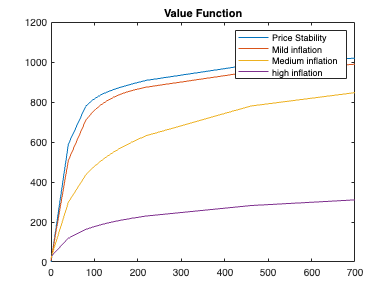

Distribution_all = 1000×4
   75.7177  141.7281   88.1477   63.9054
  177.8095   51.8639  124.7174   86.6207
   60.7281  124.9459  133.1242  137.1472
  115.9642   92.0415   61.6167  124.9638
  119.0462  139.5091  121.2891   98.8264
   81.4590   52.9040   98.5088  108.7684
   90.4584   89.7878  112.4347   90.5639
  135.6218  102.0228   89.8357  136.2409
   95.2344  164.2791  126.6893   60.0355
   82.1385  111.4729   76.1498  195.0401


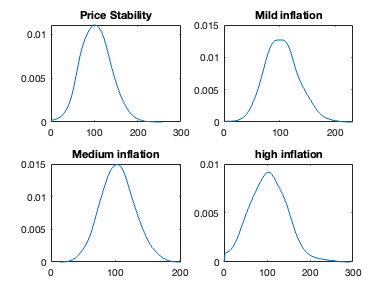

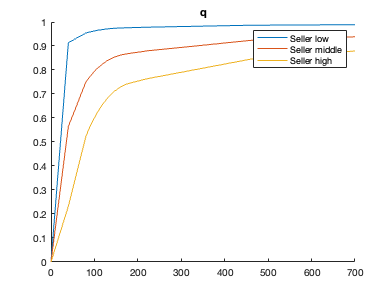

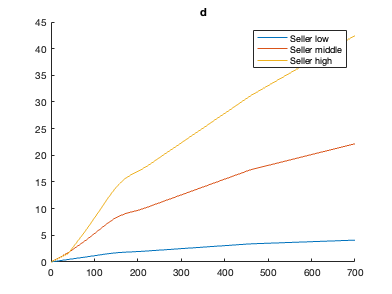

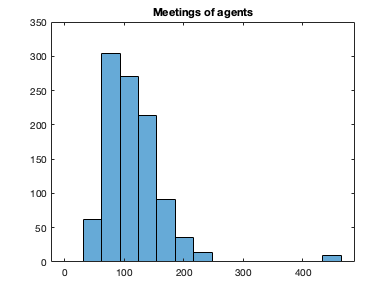

index = 1×50
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


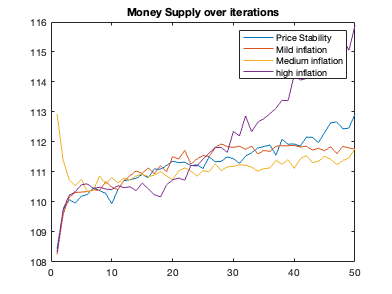

if display_plot_all==1

%Plot V
if display_plot_V==1
figure(1)
plot(m,V_all)
title('Value Function')
legend(mu_labels)

 end


%Plot Distribution Smooth
if display_plot_Distribution_smooth==1 
Distribution_all(Distribution_all==0)=0.001
    figure(2)
    hold on
for l=1:n_calibration
[f(:,l),xi(:,l)] = ksdensity(Distribution_all(:,l),'Support','positive','BoundaryCorrection'...
    ,'reflection','Bandwidth',std(Distribution_all(:,l))*smoothing_parameter); 
    subplot(2,2,l)
plot(xi(:,l),f(:,l))
title(mu_labels(1,l))
 end
end

hold off

%Plot Distribution Rough
if display_plot_Distribution_rough==1
figure(3)
histogram(Distribution_all,grids*2)
 title('Distribution of Money holdings')
 legend(mu_labels)
 end




%Plot q (first iteration)
 if display_plot_q==1
figure(4)
hold on
plot(m,q_all(:,1,1))
plot(m,q_all(:,round(grids/2),1))
plot(m,q_all(:,grids-1,1))
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('q')

 end




%Plot d (last iteration)
 if display_plot_d==1
figure(5)
hold on
plot(m,d_all(:,1,1))
plot(m,d_all(:,round(grids/2),1))
plot(m,d_all(:,grids-1,1))
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('d')
 end

%Plot cdf
if display_plot_cdf==1
figure (6)
plot(m,cdf)
title('cdf')
end


% Plot Money Savings
if display_plot_money_savings==1
m_savings_1=m'-d(:,1);
m_savings_2=m'-d(:,round(grids/2));
m_savings_3=m'-d(:,grids-1);
figure(7)
hold on
plot(m',m_savings_1)
plot(m',m_savings_2)
plot(m',m_savings_3)
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('Money Savings')
end



% Plot Mettings
if display_plot_meeting==1
for i=1:N
Meeting(1,i)=m(1,Meeting(1,i));
end
figure (8)
histogram(Meeting,grids)
title('Meetings of agents')
end



%Plot M_track_1
if display_plot_M_Track_1==1
index=[1:iterations]
figure(9)
plot(index, M_track_1)
title('Money Supply over iterations')
legend(mu_labels)
end

end

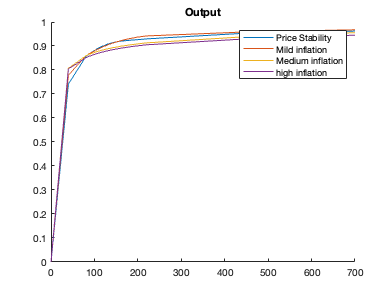


% Plot all q

 if display_plot_q_all==1
figure(10)
hold on
plot(m,q_all(:,3,1))
plot(m,q_all(:,3,2))
plot(m,q_all(:,3,3))
plot(m,q_all(:,3,4))
legend(mu_labels)
hold off
title('Output')
 end

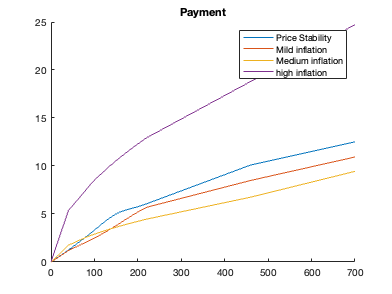


% Plot all d


  if display_plot_d_all==1
figure(11)
hold on
plot(m,d_all(:,3,1))
plot(m,d_all(:,3,2))
plot(m,d_all(:,3,3))
plot(m,d_all(:,3,4))
legend(mu_labels)
hold off
title('Payment')
 end






toc

Elapsed time is 352.568833 seconds.


## Tables

data_table=[average_q;average_price;std_distribution;velocity; average_real_balances]'

data_table = 4×5
    0.8436    5.7827   33.6240    0.0432   19.5280
    0.8491    4.2357   29.6418    0.0322   26.3856
    0.8577    4.1058   25.5836    0.0315   27.2245
    0.8449   12.0541   42.1939    0.0879    9.6136


figure(20)
 t=uitable(figure,'Data', data_table, 'Position', [100 100 500 200])

t =   Table with properties:

                Data: [4×5 double]
         ColumnWidth: 'auto'
      ColumnEditable: []
    CellEditCallback: ''
            Position: [100 100 500 200]
               Units: 'pixels'

  Show all properties


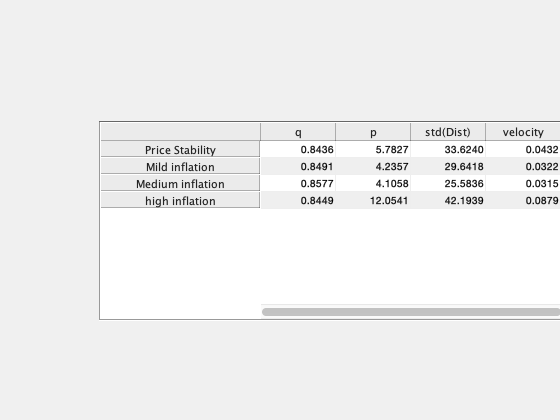

set(t, 'columnname', {'q', 'p','std(Dist)','velocity', 'real balances'})
set(t, 'rowname', mu_labels)